# Create and Train a Deep Learning Model

Script for creating and training a deep learning network with the following properties:

Run this script to create the network layers, import training and validation data, and train the network. The network layers are stored in the workspace variable `lgraph`. The trained network is stored in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 07-Dec-2022 14:33:56

## Load Initial Parameters

Load parameters for network initialization. For transfer learning, the network initialization parameters are the parameters of the initial pretrained network.

trainingSetup = load("C:\Users\roadk\Documents\EECE 314\Project\trainingSetup_2022_12_07__14_33_53.mat");

## Import Data

Import training and validation data.

imdsTrain = imageDatastore("C:\Users\roadk\Documents\EECE 314\Project\ReorganizedImages","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7);

## Augmentation Settings

imageAugmenter = imageDataAugmenter(...
    "RandRotation",[-90 90],...
    "RandScale",[1 2],...
    "RandXReflection",true);

% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([224 224 3],imdsTrain,"DataAugmentation",imageAugmenter);
augimdsValidation = augmentedImageDatastore([224 224 3],imdsValidation);

## Set Training Options

Specify options to use when training.

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","gpu",...
    "InitialLearnRate",0.001,...
    "MiniBatchSize",64,...
    "Shuffle","every-epoch",...
    "ValidationFrequency",5,...
    "Plots","training-progress",...
    "ValidationData",augimdsValidation);

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([224 224 3],"Name","input_1","Normalization","zscore","Mean",trainingSetup.input_1.Mean,"StandardDeviation",trainingSetup.input_1.StandardDeviation)
    convolution2dLayer([3 3],32,"Name","Conv1","Padding","same","Stride",[2 2],"Bias",trainingSetup.Conv1.Bias,"Weights",trainingSetup.Conv1.Weights)
    batchNormalizationLayer("Name","bn_Conv1","Epsilon",0.001,"Offset",trainingSetup.bn_Conv1.Offset,"Scale",trainingSetup.bn_Conv1.Scale,"TrainedMean",trainingSetup.bn_Conv1.TrainedMean,"TrainedVariance",trainingSetup.bn_Conv1.TrainedVariance)
    clippedReluLayer(6,"Name","Conv1_relu")
    groupedConvolution2dLayer([3 3],1,32,"Name","expanded_conv_depthwise","Padding","same","Bias",trainingSetup.expanded_conv_depthwise.Bias,"Weights",trainingSetup.expanded_conv_depthwise.Weights)
    batchNormalizationLayer("Name","expanded_conv_depthwise_BN","Epsilon",0.001,"Offset",trainingSetup.expanded_conv_depthwise_BN.Offset,"Scale",trainingSetup.expanded_conv_depthwise_BN.Scale,"TrainedMean",trainingSetup.expanded_conv_depthwise_BN.TrainedMean,"TrainedVariance",trainingSetup.expanded_conv_depthwise_BN.TrainedVariance)
    clippedReluLayer(6,"Name","expanded_conv_depthwise_relu")
    convolution2dLayer([1 1],16,"Name","expanded_conv_project","Padding","same","Bias",trainingSetup.expanded_conv_project.Bias,"Weights",trainingSetup.expanded_conv_project.Weights)
    batchNormalizationLayer("Name","expanded_conv_project_BN","Epsilon",0.001,"Offset",trainingSetup.expanded_conv_project_BN.Offset,"Scale",trainingSetup.expanded_conv_project_BN.Scale,"TrainedMean",trainingSetup.expanded_conv_project_BN.TrainedMean,"TrainedVariance",trainingSetup.expanded_conv_project_BN.TrainedVariance)
    convolution2dLayer([1 1],96,"Name","block_1_expand","Padding","same","Bias",trainingSetup.block_1_expand.Bias,"Weights",trainingSetup.block_1_expand.Weights)
    batchNormalizationLayer("Name","block_1_expand_BN","Epsilon",0.001,"Offset",trainingSetup.block_1_expand_BN.Offset,"Scale",trainingSetup.block_1_expand_BN.Scale,"TrainedMean",trainingSetup.block_1_expand_BN.TrainedMean,"TrainedVariance",trainingSetup.block_1_expand_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_1_expand_relu")
    groupedConvolution2dLayer([3 3],1,96,"Name","block_1_depthwise","Padding","same","Stride",[2 2],"Bias",trainingSetup.block_1_depthwise.Bias,"Weights",trainingSetup.block_1_depthwise.Weights)
    batchNormalizationLayer("Name","block_1_depthwise_BN","Epsilon",0.001,"Offset",trainingSetup.block_1_depthwise_BN.Offset,"Scale",trainingSetup.block_1_depthwise_BN.Scale,"TrainedMean",trainingSetup.block_1_depthwise_BN.TrainedMean,"TrainedVariance",trainingSetup.block_1_depthwise_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_1_depthwise_relu")
    convolution2dLayer([1 1],24,"Name","block_1_project","Padding","same","Bias",trainingSetup.block_1_project.Bias,"Weights",trainingSetup.block_1_project.Weights)
    batchNormalizationLayer("Name","block_1_project_BN","Epsilon",0.001,"Offset",trainingSetup.block_1_project_BN.Offset,"Scale",trainingSetup.block_1_project_BN.Scale,"TrainedMean",trainingSetup.block_1_project_BN.TrainedMean,"TrainedVariance",trainingSetup.block_1_project_BN.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","block_2_expand","Padding","same","Bias",trainingSetup.block_2_expand.Bias,"Weights",trainingSetup.block_2_expand.Weights)
    batchNormalizationLayer("Name","block_2_expand_BN","Epsilon",0.001,"Offset",trainingSetup.block_2_expand_BN.Offset,"Scale",trainingSetup.block_2_expand_BN.Scale,"TrainedMean",trainingSetup.block_2_expand_BN.TrainedMean,"TrainedVariance",trainingSetup.block_2_expand_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_2_expand_relu")
    groupedConvolution2dLayer([3 3],1,144,"Name","block_2_depthwise","Padding","same","Bias",trainingSetup.block_2_depthwise.Bias,"Weights",trainingSetup.block_2_depthwise.Weights)
    batchNormalizationLayer("Name","block_2_depthwise_BN","Epsilon",0.001,"Offset",trainingSetup.block_2_depthwise_BN.Offset,"Scale",trainingSetup.block_2_depthwise_BN.Scale,"TrainedMean",trainingSetup.block_2_depthwise_BN.TrainedMean,"TrainedVariance",trainingSetup.block_2_depthwise_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_2_depthwise_relu")
    convolution2dLayer([1 1],24,"Name","block_2_project","Padding","same","Bias",trainingSetup.block_2_project.Bias,"Weights",trainingSetup.block_2_project.Weights)
    batchNormalizationLayer("Name","block_2_project_BN","Epsilon",0.001,"Offset",trainingSetup.block_2_project_BN.Offset,"Scale",trainingSetup.block_2_project_BN.Scale,"TrainedMean",trainingSetup.block_2_project_BN.TrainedMean,"TrainedVariance",trainingSetup.block_2_project_BN.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","block_2_add")
    convolution2dLayer([1 1],144,"Name","block_3_expand","Padding","same","Bias",trainingSetup.block_3_expand.Bias,"Weights",trainingSetup.block_3_expand.Weights)
    batchNormalizationLayer("Name","block_3_expand_BN","Epsilon",0.001,"Offset",trainingSetup.block_3_expand_BN.Offset,"Scale",trainingSetup.block_3_expand_BN.Scale,"TrainedMean",trainingSetup.block_3_expand_BN.TrainedMean,"TrainedVariance",trainingSetup.block_3_expand_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_3_expand_relu")
    groupedConvolution2dLayer([3 3],1,144,"Name","block_3_depthwise","Padding","same","Stride",[2 2],"Bias",trainingSetup.block_3_depthwise.Bias,"Weights",trainingSetup.block_3_depthwise.Weights)
    batchNormalizationLayer("Name","block_3_depthwise_BN","Epsilon",0.001,"Offset",trainingSetup.block_3_depthwise_BN.Offset,"Scale",trainingSetup.block_3_depthwise_BN.Scale,"TrainedMean",trainingSetup.block_3_depthwise_BN.TrainedMean,"TrainedVariance",trainingSetup.block_3_depthwise_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_3_depthwise_relu")
    convolution2dLayer([1 1],32,"Name","block_3_project","Padding","same","Bias",trainingSetup.block_3_project.Bias,"Weights",trainingSetup.block_3_project.Weights)
    batchNormalizationLayer("Name","block_3_project_BN","Epsilon",0.001,"Offset",trainingSetup.block_3_project_BN.Offset,"Scale",trainingSetup.block_3_project_BN.Scale,"TrainedMean",trainingSetup.block_3_project_BN.TrainedMean,"TrainedVariance",trainingSetup.block_3_project_BN.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","block_4_expand","Padding","same","Bias",trainingSetup.block_4_expand.Bias,"Weights",trainingSetup.block_4_expand.Weights)
    batchNormalizationLayer("Name","block_4_expand_BN","Epsilon",0.001,"Offset",trainingSetup.block_4_expand_BN.Offset,"Scale",trainingSetup.block_4_expand_BN.Scale,"TrainedMean",trainingSetup.block_4_expand_BN.TrainedMean,"TrainedVariance",trainingSetup.block_4_expand_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_4_expand_relu")
    groupedConvolution2dLayer([3 3],1,192,"Name","block_4_depthwise","Padding","same","Bias",trainingSetup.block_4_depthwise.Bias,"Weights",trainingSetup.block_4_depthwise.Weights)
    batchNormalizationLayer("Name","block_4_depthwise_BN","Epsilon",0.001,"Offset",trainingSetup.block_4_depthwise_BN.Offset,"Scale",trainingSetup.block_4_depthwise_BN.Scale,"TrainedMean",trainingSetup.block_4_depthwise_BN.TrainedMean,"TrainedVariance",trainingSetup.block_4_depthwise_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_4_depthwise_relu")
    convolution2dLayer([1 1],32,"Name","block_4_project","Padding","same","Bias",trainingSetup.block_4_project.Bias,"Weights",trainingSetup.block_4_project.Weights)
    batchNormalizationLayer("Name","block_4_project_BN","Epsilon",0.001,"Offset",trainingSetup.block_4_project_BN.Offset,"Scale",trainingSetup.block_4_project_BN.Scale,"TrainedMean",trainingSetup.block_4_project_BN.TrainedMean,"TrainedVariance",trainingSetup.block_4_project_BN.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","block_4_add");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","block_5_expand","Padding","same","Bias",trainingSetup.block_5_expand.Bias,"Weights",trainingSetup.block_5_expand.Weights)
    batchNormalizationLayer("Name","block_5_expand_BN","Epsilon",0.001,"Offset",trainingSetup.block_5_expand_BN.Offset,"Scale",trainingSetup.block_5_expand_BN.Scale,"TrainedMean",trainingSetup.block_5_expand_BN.TrainedMean,"TrainedVariance",trainingSetup.block_5_expand_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_5_expand_relu")
    groupedConvolution2dLayer([3 3],1,192,"Name","block_5_depthwise","Padding","same","Bias",trainingSetup.block_5_depthwise.Bias,"Weights",trainingSetup.block_5_depthwise.Weights)
    batchNormalizationLayer("Name","block_5_depthwise_BN","Epsilon",0.001,"Offset",trainingSetup.block_5_depthwise_BN.Offset,"Scale",trainingSetup.block_5_depthwise_BN.Scale,"TrainedMean",trainingSetup.block_5_depthwise_BN.TrainedMean,"TrainedVariance",trainingSetup.block_5_depthwise_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_5_depthwise_relu")
    convolution2dLayer([1 1],32,"Name","block_5_project","Padding","same","Bias",trainingSetup.block_5_project.Bias,"Weights",trainingSetup.block_5_project.Weights)
    batchNormalizationLayer("Name","block_5_project_BN","Epsilon",0.001,"Offset",trainingSetup.block_5_project_BN.Offset,"Scale",trainingSetup.block_5_project_BN.Scale,"TrainedMean",trainingSetup.block_5_project_BN.TrainedMean,"TrainedVariance",trainingSetup.block_5_project_BN.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","block_5_add")
    convolution2dLayer([1 1],192,"Name","block_6_expand","Padding","same","Bias",trainingSetup.block_6_expand.Bias,"Weights",trainingSetup.block_6_expand.Weights)
    batchNormalizationLayer("Name","block_6_expand_BN","Epsilon",0.001,"Offset",trainingSetup.block_6_expand_BN.Offset,"Scale",trainingSetup.block_6_expand_BN.Scale,"TrainedMean",trainingSetup.block_6_expand_BN.TrainedMean,"TrainedVariance",trainingSetup.block_6_expand_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_6_expand_relu")
    groupedConvolution2dLayer([3 3],1,192,"Name","block_6_depthwise","Padding","same","Stride",[2 2],"Bias",trainingSetup.block_6_depthwise.Bias,"Weights",trainingSetup.block_6_depthwise.Weights)
    batchNormalizationLayer("Name","block_6_depthwise_BN","Epsilon",0.001,"Offset",trainingSetup.block_6_depthwise_BN.Offset,"Scale",trainingSetup.block_6_depthwise_BN.Scale,"TrainedMean",trainingSetup.block_6_depthwise_BN.TrainedMean,"TrainedVariance",trainingSetup.block_6_depthwise_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_6_depthwise_relu")
    convolution2dLayer([1 1],64,"Name","block_6_project","Padding","same","Bias",trainingSetup.block_6_project.Bias,"Weights",trainingSetup.block_6_project.Weights)
    batchNormalizationLayer("Name","block_6_project_BN","Epsilon",0.001,"Offset",trainingSetup.block_6_project_BN.Offset,"Scale",trainingSetup.block_6_project_BN.Scale,"TrainedMean",trainingSetup.block_6_project_BN.TrainedMean,"TrainedVariance",trainingSetup.block_6_project_BN.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","block_7_expand","Padding","same","Bias",trainingSetup.block_7_expand.Bias,"Weights",trainingSetup.block_7_expand.Weights)
    batchNormalizationLayer("Name","block_7_expand_BN","Epsilon",0.001,"Offset",trainingSetup.block_7_expand_BN.Offset,"Scale",trainingSetup.block_7_expand_BN.Scale,"TrainedMean",trainingSetup.block_7_expand_BN.TrainedMean,"TrainedVariance",trainingSetup.block_7_expand_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_7_expand_relu")
    groupedConvolution2dLayer([3 3],1,384,"Name","block_7_depthwise","Padding","same","Bias",trainingSetup.block_7_depthwise.Bias,"Weights",trainingSetup.block_7_depthwise.Weights)
    batchNormalizationLayer("Name","block_7_depthwise_BN","Epsilon",0.001,"Offset",trainingSetup.block_7_depthwise_BN.Offset,"Scale",trainingSetup.block_7_depthwise_BN.Scale,"TrainedMean",trainingSetup.block_7_depthwise_BN.TrainedMean,"TrainedVariance",trainingSetup.block_7_depthwise_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_7_depthwise_relu")
    convolution2dLayer([1 1],64,"Name","block_7_project","Padding","same","Bias",trainingSetup.block_7_project.Bias,"Weights",trainingSetup.block_7_project.Weights)
    batchNormalizationLayer("Name","block_7_project_BN","Epsilon",0.001,"Offset",trainingSetup.block_7_project_BN.Offset,"Scale",trainingSetup.block_7_project_BN.Scale,"TrainedMean",trainingSetup.block_7_project_BN.TrainedMean,"TrainedVariance",trainingSetup.block_7_project_BN.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","block_7_add");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","block_8_expand","Padding","same","Bias",trainingSetup.block_8_expand.Bias,"Weights",trainingSetup.block_8_expand.Weights)
    batchNormalizationLayer("Name","block_8_expand_BN","Epsilon",0.001,"Offset",trainingSetup.block_8_expand_BN.Offset,"Scale",trainingSetup.block_8_expand_BN.Scale,"TrainedMean",trainingSetup.block_8_expand_BN.TrainedMean,"TrainedVariance",trainingSetup.block_8_expand_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_8_expand_relu")
    groupedConvolution2dLayer([3 3],1,384,"Name","block_8_depthwise","Padding","same","Bias",trainingSetup.block_8_depthwise.Bias,"Weights",trainingSetup.block_8_depthwise.Weights)
    batchNormalizationLayer("Name","block_8_depthwise_BN","Epsilon",0.001,"Offset",trainingSetup.block_8_depthwise_BN.Offset,"Scale",trainingSetup.block_8_depthwise_BN.Scale,"TrainedMean",trainingSetup.block_8_depthwise_BN.TrainedMean,"TrainedVariance",trainingSetup.block_8_depthwise_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_8_depthwise_relu")
    convolution2dLayer([1 1],64,"Name","block_8_project","Padding","same","Bias",trainingSetup.block_8_project.Bias,"Weights",trainingSetup.block_8_project.Weights)
    batchNormalizationLayer("Name","block_8_project_BN","Epsilon",0.001,"Offset",trainingSetup.block_8_project_BN.Offset,"Scale",trainingSetup.block_8_project_BN.Scale,"TrainedMean",trainingSetup.block_8_project_BN.TrainedMean,"TrainedVariance",trainingSetup.block_8_project_BN.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","block_8_add");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],384,"Name","block_9_expand","Padding","same","Bias",trainingSetup.block_9_expand.Bias,"Weights",trainingSetup.block_9_expand.Weights)
    batchNormalizationLayer("Name","block_9_expand_BN","Epsilon",0.001,"Offset",trainingSetup.block_9_expand_BN.Offset,"Scale",trainingSetup.block_9_expand_BN.Scale,"TrainedMean",trainingSetup.block_9_expand_BN.TrainedMean,"TrainedVariance",trainingSetup.block_9_expand_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_9_expand_relu")
    groupedConvolution2dLayer([3 3],1,384,"Name","block_9_depthwise","Padding","same","Bias",trainingSetup.block_9_depthwise.Bias,"Weights",trainingSetup.block_9_depthwise.Weights)
    batchNormalizationLayer("Name","block_9_depthwise_BN","Epsilon",0.001,"Offset",trainingSetup.block_9_depthwise_BN.Offset,"Scale",trainingSetup.block_9_depthwise_BN.Scale,"TrainedMean",trainingSetup.block_9_depthwise_BN.TrainedMean,"TrainedVariance",trainingSetup.block_9_depthwise_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_9_depthwise_relu")
    convolution2dLayer([1 1],64,"Name","block_9_project","Padding","same","Bias",trainingSetup.block_9_project.Bias,"Weights",trainingSetup.block_9_project.Weights)
    batchNormalizationLayer("Name","block_9_project_BN","Epsilon",0.001,"Offset",trainingSetup.block_9_project_BN.Offset,"Scale",trainingSetup.block_9_project_BN.Scale,"TrainedMean",trainingSetup.block_9_project_BN.TrainedMean,"TrainedVariance",trainingSetup.block_9_project_BN.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","block_9_add")
    convolution2dLayer([1 1],384,"Name","block_10_expand","Padding","same","Bias",trainingSetup.block_10_expand.Bias,"Weights",trainingSetup.block_10_expand.Weights)
    batchNormalizationLayer("Name","block_10_expand_BN","Epsilon",0.001,"Offset",trainingSetup.block_10_expand_BN.Offset,"Scale",trainingSetup.block_10_expand_BN.Scale,"TrainedMean",trainingSetup.block_10_expand_BN.TrainedMean,"TrainedVariance",trainingSetup.block_10_expand_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_10_expand_relu")
    groupedConvolution2dLayer([3 3],1,384,"Name","block_10_depthwise","Padding","same","Bias",trainingSetup.block_10_depthwise.Bias,"Weights",trainingSetup.block_10_depthwise.Weights)
    batchNormalizationLayer("Name","block_10_depthwise_BN","Epsilon",0.001,"Offset",trainingSetup.block_10_depthwise_BN.Offset,"Scale",trainingSetup.block_10_depthwise_BN.Scale,"TrainedMean",trainingSetup.block_10_depthwise_BN.TrainedMean,"TrainedVariance",trainingSetup.block_10_depthwise_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_10_depthwise_relu")
    convolution2dLayer([1 1],96,"Name","block_10_project","Padding","same","Bias",trainingSetup.block_10_project.Bias,"Weights",trainingSetup.block_10_project.Weights)
    batchNormalizationLayer("Name","block_10_project_BN","Epsilon",0.001,"Offset",trainingSetup.block_10_project_BN.Offset,"Scale",trainingSetup.block_10_project_BN.Scale,"TrainedMean",trainingSetup.block_10_project_BN.TrainedMean,"TrainedVariance",trainingSetup.block_10_project_BN.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],576,"Name","block_11_expand","Padding","same","Bias",trainingSetup.block_11_expand.Bias,"Weights",trainingSetup.block_11_expand.Weights)
    batchNormalizationLayer("Name","block_11_expand_BN","Epsilon",0.001,"Offset",trainingSetup.block_11_expand_BN.Offset,"Scale",trainingSetup.block_11_expand_BN.Scale,"TrainedMean",trainingSetup.block_11_expand_BN.TrainedMean,"TrainedVariance",trainingSetup.block_11_expand_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_11_expand_relu")
    groupedConvolution2dLayer([3 3],1,576,"Name","block_11_depthwise","Padding","same","Bias",trainingSetup.block_11_depthwise.Bias,"Weights",trainingSetup.block_11_depthwise.Weights)
    batchNormalizationLayer("Name","block_11_depthwise_BN","Epsilon",0.001,"Offset",trainingSetup.block_11_depthwise_BN.Offset,"Scale",trainingSetup.block_11_depthwise_BN.Scale,"TrainedMean",trainingSetup.block_11_depthwise_BN.TrainedMean,"TrainedVariance",trainingSetup.block_11_depthwise_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_11_depthwise_relu")
    convolution2dLayer([1 1],96,"Name","block_11_project","Padding","same","Bias",trainingSetup.block_11_project.Bias,"Weights",trainingSetup.block_11_project.Weights)
    batchNormalizationLayer("Name","block_11_project_BN","Epsilon",0.001,"Offset",trainingSetup.block_11_project_BN.Offset,"Scale",trainingSetup.block_11_project_BN.Scale,"TrainedMean",trainingSetup.block_11_project_BN.TrainedMean,"TrainedVariance",trainingSetup.block_11_project_BN.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","block_11_add");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],576,"Name","block_12_expand","Padding","same","Bias",trainingSetup.block_12_expand.Bias,"Weights",trainingSetup.block_12_expand.Weights)
    batchNormalizationLayer("Name","block_12_expand_BN","Epsilon",0.001,"Offset",trainingSetup.block_12_expand_BN.Offset,"Scale",trainingSetup.block_12_expand_BN.Scale,"TrainedMean",trainingSetup.block_12_expand_BN.TrainedMean,"TrainedVariance",trainingSetup.block_12_expand_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_12_expand_relu")
    groupedConvolution2dLayer([3 3],1,576,"Name","block_12_depthwise","Padding","same","Bias",trainingSetup.block_12_depthwise.Bias,"Weights",trainingSetup.block_12_depthwise.Weights)
    batchNormalizationLayer("Name","block_12_depthwise_BN","Epsilon",0.001,"Offset",trainingSetup.block_12_depthwise_BN.Offset,"Scale",trainingSetup.block_12_depthwise_BN.Scale,"TrainedMean",trainingSetup.block_12_depthwise_BN.TrainedMean,"TrainedVariance",trainingSetup.block_12_depthwise_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_12_depthwise_relu")
    convolution2dLayer([1 1],96,"Name","block_12_project","Padding","same","Bias",trainingSetup.block_12_project.Bias,"Weights",trainingSetup.block_12_project.Weights)
    batchNormalizationLayer("Name","block_12_project_BN","Epsilon",0.001,"Offset",trainingSetup.block_12_project_BN.Offset,"Scale",trainingSetup.block_12_project_BN.Scale,"TrainedMean",trainingSetup.block_12_project_BN.TrainedMean,"TrainedVariance",trainingSetup.block_12_project_BN.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","block_12_add")
    convolution2dLayer([1 1],576,"Name","block_13_expand","Padding","same","Bias",trainingSetup.block_13_expand.Bias,"Weights",trainingSetup.block_13_expand.Weights)
    batchNormalizationLayer("Name","block_13_expand_BN","Epsilon",0.001,"Offset",trainingSetup.block_13_expand_BN.Offset,"Scale",trainingSetup.block_13_expand_BN.Scale,"TrainedMean",trainingSetup.block_13_expand_BN.TrainedMean,"TrainedVariance",trainingSetup.block_13_expand_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_13_expand_relu")
    groupedConvolution2dLayer([3 3],1,576,"Name","block_13_depthwise","Padding","same","Stride",[2 2],"Bias",trainingSetup.block_13_depthwise.Bias,"Weights",trainingSetup.block_13_depthwise.Weights)
    batchNormalizationLayer("Name","block_13_depthwise_BN","Epsilon",0.001,"Offset",trainingSetup.block_13_depthwise_BN.Offset,"Scale",trainingSetup.block_13_depthwise_BN.Scale,"TrainedMean",trainingSetup.block_13_depthwise_BN.TrainedMean,"TrainedVariance",trainingSetup.block_13_depthwise_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_13_depthwise_relu")
    convolution2dLayer([1 1],160,"Name","block_13_project","Padding","same","Bias",trainingSetup.block_13_project.Bias,"Weights",trainingSetup.block_13_project.Weights)
    batchNormalizationLayer("Name","block_13_project_BN","Epsilon",0.001,"Offset",trainingSetup.block_13_project_BN.Offset,"Scale",trainingSetup.block_13_project_BN.Scale,"TrainedMean",trainingSetup.block_13_project_BN.TrainedMean,"TrainedVariance",trainingSetup.block_13_project_BN.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],960,"Name","block_14_expand","Padding","same","Bias",trainingSetup.block_14_expand.Bias,"Weights",trainingSetup.block_14_expand.Weights)
    batchNormalizationLayer("Name","block_14_expand_BN","Epsilon",0.001,"Offset",trainingSetup.block_14_expand_BN.Offset,"Scale",trainingSetup.block_14_expand_BN.Scale,"TrainedMean",trainingSetup.block_14_expand_BN.TrainedMean,"TrainedVariance",trainingSetup.block_14_expand_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_14_expand_relu")
    groupedConvolution2dLayer([3 3],1,960,"Name","block_14_depthwise","Padding","same","Bias",trainingSetup.block_14_depthwise.Bias,"Weights",trainingSetup.block_14_depthwise.Weights)
    batchNormalizationLayer("Name","block_14_depthwise_BN","Epsilon",0.001,"Offset",trainingSetup.block_14_depthwise_BN.Offset,"Scale",trainingSetup.block_14_depthwise_BN.Scale,"TrainedMean",trainingSetup.block_14_depthwise_BN.TrainedMean,"TrainedVariance",trainingSetup.block_14_depthwise_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_14_depthwise_relu")
    convolution2dLayer([1 1],160,"Name","block_14_project","Padding","same","Bias",trainingSetup.block_14_project.Bias,"Weights",trainingSetup.block_14_project.Weights)
    batchNormalizationLayer("Name","block_14_project_BN","Epsilon",0.001,"Offset",trainingSetup.block_14_project_BN.Offset,"Scale",trainingSetup.block_14_project_BN.Scale,"TrainedMean",trainingSetup.block_14_project_BN.TrainedMean,"TrainedVariance",trainingSetup.block_14_project_BN.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","block_14_add");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],960,"Name","block_15_expand","Padding","same","Bias",trainingSetup.block_15_expand.Bias,"Weights",trainingSetup.block_15_expand.Weights)
    batchNormalizationLayer("Name","block_15_expand_BN","Epsilon",0.001,"Offset",trainingSetup.block_15_expand_BN.Offset,"Scale",trainingSetup.block_15_expand_BN.Scale,"TrainedMean",trainingSetup.block_15_expand_BN.TrainedMean,"TrainedVariance",trainingSetup.block_15_expand_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_15_expand_relu")
    groupedConvolution2dLayer([3 3],1,960,"Name","block_15_depthwise","Padding","same","Bias",trainingSetup.block_15_depthwise.Bias,"Weights",trainingSetup.block_15_depthwise.Weights)
    batchNormalizationLayer("Name","block_15_depthwise_BN","Epsilon",0.001,"Offset",trainingSetup.block_15_depthwise_BN.Offset,"Scale",trainingSetup.block_15_depthwise_BN.Scale,"TrainedMean",trainingSetup.block_15_depthwise_BN.TrainedMean,"TrainedVariance",trainingSetup.block_15_depthwise_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_15_depthwise_relu")
    convolution2dLayer([1 1],160,"Name","block_15_project","Padding","same","Bias",trainingSetup.block_15_project.Bias,"Weights",trainingSetup.block_15_project.Weights)
    batchNormalizationLayer("Name","block_15_project_BN","Epsilon",0.001,"Offset",trainingSetup.block_15_project_BN.Offset,"Scale",trainingSetup.block_15_project_BN.Scale,"TrainedMean",trainingSetup.block_15_project_BN.TrainedMean,"TrainedVariance",trainingSetup.block_15_project_BN.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","block_15_add")
    convolution2dLayer([1 1],960,"Name","block_16_expand","Padding","same","Bias",trainingSetup.block_16_expand.Bias,"Weights",trainingSetup.block_16_expand.Weights)
    batchNormalizationLayer("Name","block_16_expand_BN","Epsilon",0.001,"Offset",trainingSetup.block_16_expand_BN.Offset,"Scale",trainingSetup.block_16_expand_BN.Scale,"TrainedMean",trainingSetup.block_16_expand_BN.TrainedMean,"TrainedVariance",trainingSetup.block_16_expand_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_16_expand_relu")
    groupedConvolution2dLayer([3 3],1,960,"Name","block_16_depthwise","Padding","same","Bias",trainingSetup.block_16_depthwise.Bias,"Weights",trainingSetup.block_16_depthwise.Weights)
    batchNormalizationLayer("Name","block_16_depthwise_BN","Epsilon",0.001,"Offset",trainingSetup.block_16_depthwise_BN.Offset,"Scale",trainingSetup.block_16_depthwise_BN.Scale,"TrainedMean",trainingSetup.block_16_depthwise_BN.TrainedMean,"TrainedVariance",trainingSetup.block_16_depthwise_BN.TrainedVariance)
    clippedReluLayer(6,"Name","block_16_depthwise_relu")
    convolution2dLayer([1 1],320,"Name","block_16_project","Padding","same","Bias",trainingSetup.block_16_project.Bias,"Weights",trainingSetup.block_16_project.Weights)
    batchNormalizationLayer("Name","block_16_project_BN","Epsilon",0.001,"Offset",trainingSetup.block_16_project_BN.Offset,"Scale",trainingSetup.block_16_project_BN.Scale,"TrainedMean",trainingSetup.block_16_project_BN.TrainedMean,"TrainedVariance",trainingSetup.block_16_project_BN.TrainedVariance)
    convolution2dLayer([1 1],1280,"Name","Conv_1","Bias",trainingSetup.Conv_1.Bias,"Weights",trainingSetup.Conv_1.Weights)
    batchNormalizationLayer("Name","Conv_1_bn","Epsilon",0.001,"Offset",trainingSetup.Conv_1_bn.Offset,"Scale",trainingSetup.Conv_1_bn.Scale,"TrainedMean",trainingSetup.Conv_1_bn.TrainedMean,"TrainedVariance",trainingSetup.Conv_1_bn.TrainedVariance)
    clippedReluLayer(6,"Name","out_relu")
    globalAveragePooling2dLayer("Name","global_average_pooling2d_1")
    fullyConnectedLayer(7,"Name","fc","BiasLearnRateFactor",10,"WeightLearnRateFactor",10)
    softmaxLayer("Name","Logits_softmax")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"block_1_project_BN","block_2_expand");
lgraph = connectLayers(lgraph,"block_1_project_BN","block_2_add/in2");
lgraph = connectLayers(lgraph,"block_2_project_BN","block_2_add/in1");
lgraph = connectLayers(lgraph,"block_3_project_BN","block_4_expand");
lgraph = connectLayers(lgraph,"block_3_project_BN","block_4_add/in2");
lgraph = connectLayers(lgraph,"block_4_project_BN","block_4_add/in1");
lgraph = connectLayers(lgraph,"block_4_add","block_5_expand");
lgraph = connectLayers(lgraph,"block_4_add","block_5_add/in2");
lgraph = connectLayers(lgraph,"block_5_project_BN","block_5_add/in1");
lgraph = connectLayers(lgraph,"block_6_project_BN","block_7_expand");
lgraph = connectLayers(lgraph,"block_6_project_BN","block_7_add/in2");
lgraph = connectLayers(lgraph,"block_7_project_BN","block_7_add/in1");
lgraph = connectLayers(lgraph,"block_7_add","block_8_expand");
lgraph = connectLayers(lgraph,"block_7_add","block_8_add/in2");
lgraph = connectLayers(lgraph,"block_8_project_BN","block_8_add/in1");
lgraph = connectLayers(lgraph,"block_8_add","block_9_expand");
lgraph = connectLayers(lgraph,"block_8_add","block_9_add/in2");
lgraph = connectLayers(lgraph,"block_9_project_BN","block_9_add/in1");
lgraph = connectLayers(lgraph,"block_10_project_BN","block_11_expand");
lgraph = connectLayers(lgraph,"block_10_project_BN","block_11_add/in2");
lgraph = connectLayers(lgraph,"block_11_project_BN","block_11_add/in1");
lgraph = connectLayers(lgraph,"block_11_add","block_12_expand");
lgraph = connectLayers(lgraph,"block_11_add","block_12_add/in2");
lgraph = connectLayers(lgraph,"block_12_project_BN","block_12_add/in1");
lgraph = connectLayers(lgraph,"block_13_project_BN","block_14_expand");
lgraph = connectLayers(lgraph,"block_13_project_BN","block_14_add/in2");
lgraph = connectLayers(lgraph,"block_14_project_BN","block_14_add/in1");
lgraph = connectLayers(lgraph,"block_14_add","block_15_expand");
lgraph = connectLayers(lgraph,"block_14_add","block_15_add/in2");
lgraph = connectLayers(lgraph,"block_15_project_BN","block_15_add/in1");

## Train Network

Train the network using the specified options and training data.

Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:06 |        6.25% |       44.91% |       2.3433 |       1.6212 |          0.0010 |


|       1 |           5 |       00:00:16 |       75.00% |       66.94% |       1.2520 |       1.6323 |          0.0010 |


|       1 |          10 |       00:00:25 |       53.13% |       60.32% |       1.4700 |       1.2526 |          0.0010 |


|       1 |          15 |       00:00:34 |       68.75% |       67.24% |       1.1371 |       1.2894 |          0.0010 |


|       1 |          20 |       00:00:45 |       73.44% |       60.85% |       0.7715 |       1.1722 |          0.0010 |


|       1 |          25 |       00:02:09 |       67.19% |       68.08% |       0.9931 |       1.0599 |          0.0010 |


|       1 |          30 |       00:03:08 |       71.88% |       66.78% |       0.8401 |       1.0121 |          0.0010 |


|       1 |          35 |       00:03:19 |       71.88% |       67.84% |       0.7546 |       0.9752 |          0.0010 |


|       1 |          40 |       00:03:28 |       57.81% |       67.44% |       1.0215 |       0.9294 |          0.0010 |


|       1 |          45 |       00:03:38 |       62.50% |       68.31% |       0.9980 |       0.9268 |          0.0010 |


|       1 |          50 |       00:03:49 |       71.88% |       70.11% |       0.7321 |       0.9092 |          0.0010 |


|       1 |          55 |       00:04:01 |       67.19% |       69.57% |       0.7966 |       0.8769 |          0.0010 |


|       1 |          60 |       00:05:42 |       71.88% |       69.51% |       0.8790 |       0.8695 |          0.0010 |


|       1 |          65 |       00:05:53 |       84.38% |       70.61% |       0.5329 |       0.8396 |          0.0010 |


|       1 |          70 |       00:06:09 |       79.69% |       70.61% |       0.5596 |       0.9080 |          0.0010 |


|       1 |          75 |       00:06:32 |       67.19% |       68.71% |       0.8243 |       0.8630 |          0.0010 |


|       1 |          80 |       00:07:11 |       65.63% |       69.87% |       0.8321 |       0.8640 |          0.0010 |


|       1 |          85 |       00:08:19 |       62.50% |       70.64% |       1.0503 |       0.8529 |          0.0010 |


|       1 |          90 |       00:08:29 |       78.13% |       68.34% |       0.7087 |       0.8595 |          0.0010 |


|       1 |          95 |       00:08:51 |       82.81% |       70.57% |       0.5988 |       0.8620 |          0.0010 |


|       1 |         100 |       00:09:01 |       76.56% |       70.71% |       0.6312 |       0.8528 |          0.0010 |


|       1 |         105 |       00:09:10 |       78.13% |       64.75% |       0.6535 |       0.9065 |          0.0010 |


|       2 |         110 |       00:09:20 |       68.75% |       71.17% |       0.7149 |       0.8896 |          0.0010 |


|       2 |         115 |       00:09:29 |       78.13% |       71.01% |       0.5820 |       0.8247 |          0.0010 |


|       2 |         120 |       00:09:37 |       82.81% |       70.71% |       0.5496 |       0.8263 |          0.0010 |


|       2 |         125 |       00:09:47 |       73.44% |       70.31% |       0.6393 |       0.8592 |          0.0010 |


|       2 |         130 |       00:09:56 |       70.31% |       66.98% |       0.6916 |       0.8579 |          0.0010 |


|       2 |         135 |       00:10:05 |       78.13% |       71.67% |       0.6449 |       0.8402 |          0.0010 |


|       2 |         140 |       00:10:15 |       75.00% |       70.81% |       0.8883 |       0.8126 |          0.0010 |


|       2 |         145 |       00:10:24 |       71.88% |       68.58% |       0.5892 |       0.8453 |          0.0010 |


|       2 |         150 |       00:10:33 |       82.81% |       71.74% |       0.4673 |       0.8255 |          0.0010 |


|       2 |         155 |       00:10:43 |       75.00% |       72.77% |       0.6968 |       0.8265 |          0.0010 |


|       2 |         160 |       00:10:51 |       78.13% |       70.41% |       0.5528 |       0.8126 |          0.0010 |


|       2 |         165 |       00:11:01 |       64.06% |       72.07% |       0.9678 |       0.7988 |          0.0010 |


|       2 |         170 |       00:11:11 |       79.69% |       70.57% |       0.5437 |       0.8030 |          0.0010 |


|       2 |         175 |       00:11:19 |       79.69% |       71.44% |       0.5072 |       0.8428 |          0.0010 |


|       2 |         180 |       00:11:28 |       62.50% |       71.64% |       1.0803 |       0.8665 |          0.0010 |


|       2 |         185 |       00:11:38 |       78.13% |       71.14% |       0.7211 |       0.8080 |          0.0010 |


|       2 |         190 |       00:11:46 |       79.69% |       73.10% |       0.5551 |       0.7711 |          0.0010 |


|       2 |         195 |       00:11:55 |       81.25% |       73.40% |       0.5715 |       0.7948 |          0.0010 |


|       2 |         200 |       00:12:05 |       81.25% |       72.64% |       0.5852 |       0.8011 |          0.0010 |


|       2 |         205 |       00:12:14 |       81.25% |       73.74% |       0.4769 |       0.7746 |          0.0010 |


|       2 |         210 |       00:12:23 |       82.81% |       71.97% |       0.5996 |       0.7804 |          0.0010 |


|       2 |         215 |       00:12:32 |       73.44% |       71.30% |       0.6711 |       0.7864 |          0.0010 |


|       3 |         220 |       00:12:41 |       81.25% |       73.77% |       0.4949 |       0.7648 |          0.0010 |


|       3 |         225 |       00:12:50 |       76.56% |       73.74% |       0.5656 |       0.7678 |          0.0010 |


|       3 |         230 |       00:13:00 |       70.31% |       68.58% |       0.7264 |       0.8244 |          0.0010 |


|       3 |         235 |       00:13:09 |       71.88% |       71.60% |       0.7833 |       0.7967 |          0.0010 |


|       3 |         240 |       00:13:18 |       76.56% |       70.64% |       0.5945 |       0.8562 |          0.0010 |


|       3 |         245 |       00:13:28 |       78.13% |       72.34% |       0.5301 |       0.7989 |          0.0010 |


|       3 |         250 |       00:13:37 |       76.56% |       71.47% |       0.6749 |       0.8068 |          0.0010 |


|       3 |         255 |       00:13:46 |       75.00% |       71.90% |       0.5548 |       0.7970 |          0.0010 |


|       3 |         260 |       00:13:56 |       75.00% |       69.64% |       0.6205 |       0.8332 |          0.0010 |


|       3 |         265 |       00:14:05 |       73.44% |       72.74% |       0.8135 |       0.8087 |          0.0010 |


|       3 |         270 |       00:14:13 |       76.56% |       72.37% |       0.5968 |       0.7814 |          0.0010 |


|       3 |         275 |       00:14:23 |       85.94% |       71.40% |       0.4422 |       0.7663 |          0.0010 |


|       3 |         280 |       00:14:32 |       76.56% |       72.37% |       0.5256 |       0.7875 |          0.0010 |


|       3 |         285 |       00:14:40 |       70.31% |       72.20% |       0.7567 |       0.7921 |          0.0010 |


|       3 |         290 |       00:14:50 |       78.13% |       72.97% |       0.5725 |       0.7582 |          0.0010 |


|       3 |         295 |       00:14:59 |       85.94% |       73.80% |       0.4445 |       0.7575 |          0.0010 |


|       3 |         300 |       00:15:07 |       73.44% |       74.10% |       0.5922 |       0.7745 |          0.0010 |


|       3 |         305 |       00:15:17 |       87.50% |       72.60% |       0.4093 |       0.7533 |          0.0010 |


|       3 |         310 |       00:15:26 |       71.88% |       74.00% |       0.7038 |       0.7452 |          0.0010 |


|       3 |         315 |       00:15:34 |       85.94% |       74.17% |       0.4251 |       0.7419 |          0.0010 |


|       3 |         320 |       00:15:44 |       82.81% |       74.60% |       0.4741 |       0.7513 |          0.0010 |


|       3 |         325 |       00:15:53 |       75.00% |       74.60% |       0.7055 |       0.7573 |          0.0010 |


|       4 |         330 |       00:16:01 |       76.56% |       73.87% |       0.5745 |       0.7428 |          0.0010 |


|       4 |         335 |       00:16:11 |       85.94% |       73.77% |       0.3163 |       0.7586 |          0.0010 |


|       4 |         340 |       00:16:20 |       73.44% |       74.23% |       0.7376 |       0.7386 |          0.0010 |


|       4 |         345 |       00:16:29 |       68.75% |       73.74% |       0.6749 |       0.7339 |          0.0010 |


|       4 |         350 |       00:16:39 |       84.38% |       73.60% |       0.3858 |       0.7361 |          0.0010 |


|       4 |         355 |       00:16:47 |       92.19% |       73.87% |       0.2908 |       0.7701 |          0.0010 |


|       4 |         360 |       00:16:56 |       76.56% |       73.74% |       0.6266 |       0.7457 |          0.0010 |


|       4 |         365 |       00:17:06 |       84.38% |       73.93% |       0.5192 |       0.7548 |          0.0010 |


|       4 |         370 |       00:17:15 |       76.56% |       72.20% |       0.5846 |       0.7508 |          0.0010 |


|       4 |         375 |       00:17:25 |       85.94% |       72.87% |       0.4915 |       0.7627 |          0.0010 |


|       4 |         380 |       00:17:34 |       87.50% |       73.90% |       0.5074 |       0.7951 |          0.0010 |


|       4 |         385 |       00:17:43 |       81.25% |       73.07% |       0.5124 |       0.7678 |          0.0010 |


|       4 |         390 |       00:17:52 |       85.94% |       74.13% |       0.3602 |       0.7879 |          0.0010 |


|       4 |         395 |       00:18:02 |       76.56% |       73.44% |       0.5949 |       0.7835 |          0.0010 |


|       4 |         400 |       00:18:11 |       75.00% |       73.10% |       0.6002 |       0.7581 |          0.0010 |


|       4 |         405 |       00:18:19 |       78.13% |       74.73% |       0.6244 |       0.7396 |          0.0010 |


|       4 |         410 |       00:18:29 |       70.31% |       73.54% |       0.6421 |       0.7319 |          0.0010 |


|       4 |         415 |       00:18:38 |       81.25% |       73.93% |       0.5280 |       0.7284 |          0.0010 |


|       4 |         420 |       00:18:46 |       76.56% |       73.90% |       0.5756 |       0.7636 |          0.0010 |


|       4 |         425 |       00:18:56 |       76.56% |       73.64% |       0.5033 |       0.7976 |          0.0010 |


|       4 |         430 |       00:19:05 |       76.56% |       71.40% |       0.5592 |       0.7647 |          0.0010 |


|       4 |         435 |       00:19:14 |       70.31% |       70.14% |       0.6332 |       0.7768 |          0.0010 |


|       5 |         440 |       00:19:24 |       84.38% |       74.40% |       0.4631 |       0.7211 |          0.0010 |


|       5 |         445 |       00:19:33 |       85.94% |       73.34% |       0.4064 |       0.8070 |          0.0010 |


|       5 |         450 |       00:19:41 |       82.81% |       73.37% |       0.4555 |       0.7560 |          0.0010 |


|       5 |         455 |       00:19:51 |       78.13% |       71.74% |       0.5397 |       0.7508 |          0.0010 |


|       5 |         460 |       00:20:00 |       71.88% |       73.80% |       0.8908 |       0.7394 |          0.0010 |


|       5 |         465 |       00:20:09 |       65.63% |       73.87% |       1.0358 |       0.7757 |          0.0010 |


|       5 |         470 |       00:20:19 |       82.81% |       73.27% |       0.4157 |       0.7457 |          0.0010 |


|       5 |         475 |       00:20:28 |       73.44% |       73.30% |       0.5837 |       0.7496 |          0.0010 |


|       5 |         480 |       00:20:38 |       87.50% |       73.64% |       0.3888 |       0.7487 |          0.0010 |


|       5 |         485 |       00:20:48 |       78.13% |       72.74% |       0.6935 |       0.7394 |          0.0010 |


|       5 |         490 |       00:20:57 |       71.88% |       73.50% |       0.7961 |       0.7204 |          0.0010 |


|       5 |         495 |       00:21:06 |       79.69% |       74.20% |       0.5939 |       0.7343 |          0.0010 |


|       5 |         500 |       00:21:17 |       78.13% |       74.43% |       0.4404 |       0.7263 |          0.0010 |


|       5 |         505 |       00:21:26 |       76.56% |       72.07% |       0.5725 |       0.7470 |          0.0010 |


|       5 |         510 |       00:21:35 |       81.25% |       72.44% |       0.5588 |       0.7392 |          0.0010 |


|       5 |         515 |       00:21:45 |       75.00% |       74.07% |       0.7352 |       0.7409 |          0.0010 |


|       5 |         520 |       00:21:54 |       92.19% |       73.67% |       0.3485 |       0.7344 |          0.0010 |


|       5 |         525 |       00:22:02 |       89.06% |       73.27% |       0.3190 |       0.7431 |          0.0010 |


|       5 |         530 |       00:22:12 |       75.00% |       73.50% |       0.7024 |       0.7640 |          0.0010 |


|       5 |         535 |       00:22:21 |       79.69% |       73.97% |       0.5676 |       0.7234 |          0.0010 |


|       5 |         540 |       00:22:30 |       85.94% |       74.40% |       0.3979 |       0.7165 |          0.0010 |


|       5 |         545 |       00:22:40 |       76.56% |       75.07% |       0.6931 |       0.7489 |          0.0010 |


|       6 |         550 |       00:22:49 |       84.38% |       75.37% |       0.4332 |       0.7270 |          0.0010 |


|       6 |         555 |       00:23:00 |       85.94% |       73.90% |       0.4946 |       0.7117 |          0.0010 |


|       6 |         560 |       00:23:10 |       84.38% |       74.10% |       0.4621 |       0.7106 |          0.0010 |


|       6 |         565 |       00:23:20 |       87.50% |       75.30% |       0.3045 |       0.7330 |          0.0010 |


|       6 |         570 |       00:23:29 |       78.13% |       74.93% |       0.5099 |       0.7986 |          0.0010 |


|       6 |         575 |       00:23:39 |       79.69% |       74.73% |       0.4735 |       0.7404 |          0.0010 |


|       6 |         580 |       00:23:47 |       79.69% |       72.50% |       0.4382 |       0.7521 |          0.0010 |


|       6 |         585 |       00:23:56 |       89.06% |       73.77% |       0.3076 |       0.7256 |          0.0010 |


|       6 |         590 |       00:24:06 |       76.56% |       75.63% |       0.5119 |       0.7203 |          0.0010 |


|       6 |         595 |       00:24:15 |       81.25% |       75.87% |       0.5546 |       0.7299 |          0.0010 |


|       6 |         600 |       00:24:24 |       87.50% |       74.37% |       0.3589 |       0.7157 |          0.0010 |


|       6 |         605 |       00:24:34 |       84.38% |       74.20% |       0.3799 |       0.7314 |          0.0010 |


|       6 |         610 |       00:24:43 |       82.81% |       73.50% |       0.4676 |       0.7636 |          0.0010 |


|       6 |         615 |       00:24:52 |       87.50% |       73.20% |       0.3581 |       0.7278 |          0.0010 |


|       6 |         620 |       00:25:02 |       84.38% |       74.80% |       0.4231 |       0.7077 |          0.0010 |


|       6 |         625 |       00:25:11 |       82.81% |       74.03% |       0.4115 |       0.7399 |          0.0010 |


|       6 |         630 |       00:25:20 |       85.94% |       72.54% |       0.3988 |       0.7282 |          0.0010 |


|       6 |         635 |       00:25:30 |       79.69% |       74.30% |       0.5147 |       0.7456 |          0.0010 |


|       6 |         640 |       00:25:39 |       82.81% |       74.77% |       0.4010 |       0.7373 |          0.0010 |


|       6 |         645 |       00:25:48 |       89.06% |       71.54% |       0.3682 |       0.7513 |          0.0010 |


|       6 |         650 |       00:25:58 |       71.88% |       75.20% |       0.4839 |       0.6966 |          0.0010 |


|       7 |         655 |       00:26:07 |       73.44% |       74.80% |       0.6418 |       0.7424 |          0.0010 |


|       7 |         660 |       00:26:16 |       75.00% |       75.33% |       0.5484 |       0.7085 |          0.0010 |


|       7 |         665 |       00:26:26 |       82.81% |       72.04% |       0.4278 |       0.7388 |          0.0010 |


|       7 |         670 |       00:26:35 |       90.63% |       74.53% |       0.2685 |       0.7125 |          0.0010 |


|       7 |         675 |       00:26:44 |       87.50% |       74.80% |       0.3310 |       0.7326 |          0.0010 |


|       7 |         680 |       00:26:55 |       68.75% |       75.03% |       0.7368 |       0.7141 |          0.0010 |


|       7 |         685 |       00:27:03 |       78.13% |       73.97% |       0.4723 |       0.7141 |          0.0010 |


|       7 |         690 |       00:27:12 |       82.81% |       74.57% |       0.4157 |       0.6974 |          0.0010 |


|       7 |         695 |       00:27:24 |       87.50% |       75.13% |       0.4026 |       0.6946 |          0.0010 |


|       7 |         700 |       00:27:33 |       81.25% |       75.27% |       0.4249 |       0.6943 |          0.0010 |


|       7 |         705 |       00:27:42 |       78.13% |       74.70% |       0.4690 |       0.6989 |          0.0010 |


|       7 |         710 |       00:27:52 |       84.38% |       76.83% |       0.3943 |       0.6784 |          0.0010 |


|       7 |         715 |       00:28:02 |       82.81% |       75.70% |       0.5432 |       0.7326 |          0.0010 |


|       7 |         720 |       00:28:11 |       84.38% |       75.57% |       0.3245 |       0.6974 |          0.0010 |


|       7 |         725 |       00:28:21 |       87.50% |       74.53% |       0.4193 |       0.7069 |          0.0010 |


|       7 |         730 |       00:28:30 |       75.00% |       75.43% |       0.6366 |       0.6970 |          0.0010 |


|       7 |         735 |       00:28:39 |       84.38% |       75.67% |       0.4132 |       0.7155 |          0.0010 |


|       7 |         740 |       00:28:49 |       82.81% |       75.77% |       0.4478 |       0.7207 |          0.0010 |


|       7 |         745 |       00:28:58 |       84.38% |       71.27% |       0.4047 |       0.7579 |          0.0010 |


|       7 |         750 |       00:29:07 |       71.88% |       74.00% |       0.8550 |       0.7182 |          0.0010 |


|       7 |         755 |       00:29:20 |       85.94% |       76.03% |       0.3965 |       0.7413 |          0.0010 |


|       7 |         760 |       00:29:29 |       87.50% |       75.30% |       0.3467 |       0.7311 |          0.0010 |


|       8 |         765 |       00:29:38 |       87.50% |       74.77% |       0.2791 |       0.7085 |          0.0010 |


|       8 |         770 |       00:29:48 |       82.81% |       73.80% |       0.5968 |       0.7227 |          0.0010 |


|       8 |         775 |       00:29:57 |       92.19% |       75.43% |       0.2769 |       0.7164 |          0.0010 |


|       8 |         780 |       00:30:06 |       84.38% |       75.20% |       0.5705 |       0.7398 |          0.0010 |


|       8 |         785 |       00:30:16 |       84.38% |       76.00% |       0.4280 |       0.6870 |          0.0010 |


|       8 |         790 |       00:30:25 |       79.69% |       75.20% |       0.5215 |       0.6857 |          0.0010 |


|       8 |         795 |       00:30:34 |       90.63% |       76.33% |       0.3382 |       0.6776 |          0.0010 |


|       8 |         800 |       00:30:44 |       89.06% |       76.73% |       0.4069 |       0.6981 |          0.0010 |


|       8 |         805 |       00:30:53 |       84.38% |       76.30% |       0.5186 |       0.7012 |          0.0010 |


|       8 |         810 |       00:31:02 |       90.63% |       74.80% |       0.3000 |       0.7301 |          0.0010 |


|       8 |         815 |       00:31:12 |       87.50% |       76.20% |       0.2749 |       0.7073 |          0.0010 |


|       8 |         820 |       00:31:21 |       87.50% |       75.23% |       0.3199 |       0.7799 |          0.0010 |


|       8 |         825 |       00:31:30 |       84.38% |       76.20% |       0.5048 |       0.7361 |          0.0010 |


|       8 |         830 |       00:31:40 |       81.25% |       74.50% |       0.6114 |       0.7003 |          0.0010 |


|       8 |         835 |       00:31:49 |       87.50% |       70.24% |       0.3884 |       0.7615 |          0.0010 |


|       8 |         840 |       00:31:58 |       85.94% |       76.03% |       0.3703 |       0.7066 |          0.0010 |


|       8 |         845 |       00:32:11 |       75.00% |       76.33% |       0.7190 |       0.7263 |          0.0010 |


|       8 |         850 |       00:32:20 |       87.50% |       75.80% |       0.4047 |       0.7035 |          0.0010 |


|       8 |         855 |       00:32:29 |       78.13% |       75.70% |       0.5509 |       0.7003 |          0.0010 |


|       8 |         860 |       00:32:39 |       81.25% |       75.43% |       0.4603 |       0.7063 |          0.0010 |


|       8 |         865 |       00:32:48 |       84.38% |       75.53% |       0.3438 |       0.7142 |          0.0010 |


|       8 |         870 |       00:32:57 |       82.81% |       76.20% |       0.5364 |       0.6688 |          0.0010 |


|       9 |         875 |       00:33:07 |       87.50% |       76.26% |       0.2685 |       0.6722 |          0.0010 |


|       9 |         880 |       00:33:16 |       89.06% |       75.73% |       0.3084 |       0.7051 |          0.0010 |


|       9 |         885 |       00:33:25 |       89.06% |       76.33% |       0.3589 |       0.7122 |          0.0010 |


|       9 |         890 |       00:33:34 |       81.25% |       76.17% |       0.4695 |       0.7047 |          0.0010 |


|       9 |         895 |       00:33:43 |       89.06% |       76.03% |       0.3741 |       0.6958 |          0.0010 |


|       9 |         900 |       00:33:52 |       87.50% |       75.10% |       0.3745 |       0.7109 |          0.0010 |


|       9 |         905 |       00:34:02 |       89.06% |       76.23% |       0.3681 |       0.7131 |          0.0010 |


|       9 |         910 |       00:34:11 |       84.38% |       76.13% |       0.3743 |       0.7176 |          0.0010 |


|       9 |         915 |       00:34:20 |       84.38% |       77.20% |       0.3758 |       0.6724 |          0.0010 |


|       9 |         920 |       00:34:29 |       87.50% |       76.76% |       0.3061 |       0.6732 |          0.0010 |


|       9 |         925 |       00:34:38 |       84.38% |       75.90% |       0.3931 |       0.6835 |          0.0010 |


|       9 |         930 |       00:34:47 |       81.25% |       76.60% |       0.4472 |       0.6805 |          0.0010 |


|       9 |         935 |       00:34:57 |       95.31% |       77.10% |       0.2110 |       0.6679 |          0.0010 |


|       9 |         940 |       00:35:05 |       89.06% |       77.46% |       0.3275 |       0.6628 |          0.0010 |


|       9 |         945 |       00:35:14 |       89.06% |       76.73% |       0.3175 |       0.6842 |          0.0010 |


|       9 |         950 |       00:35:24 |       84.38% |       77.30% |       0.4770 |       0.6861 |          0.0010 |


|       9 |         955 |       00:35:33 |       81.25% |       76.00% |       0.6363 |       0.7012 |          0.0010 |


|       9 |         960 |       00:35:41 |       82.81% |       73.93% |       0.3444 |       0.7389 |          0.0010 |


|       9 |         965 |       00:35:51 |       79.69% |       75.60% |       0.4650 |       0.7394 |          0.0010 |


|       9 |         970 |       00:36:00 |       81.25% |       75.67% |       0.4524 |       0.7000 |          0.0010 |


|       9 |         975 |       00:36:09 |       81.25% |       75.53% |       0.4810 |       0.6897 |          0.0010 |


|       9 |         980 |       00:36:18 |       78.13% |       76.70% |       0.4641 |       0.6685 |          0.0010 |


|      10 |         985 |       00:36:27 |       89.06% |       76.46% |       0.3373 |       0.6946 |          0.0010 |


|      10 |         990 |       00:36:36 |       79.69% |       76.70% |       0.3989 |       0.7109 |          0.0010 |


|      10 |         995 |       00:36:46 |       79.69% |       76.07% |       0.4707 |       0.6886 |          0.0010 |


|      10 |        1000 |       00:36:54 |       89.06% |       75.37% |       0.3742 |       0.6872 |          0.0010 |


|      10 |        1005 |       00:37:03 |       92.19% |       75.83% |       0.2898 |       0.7093 |          0.0010 |


|      10 |        1010 |       00:37:13 |       78.13% |       76.30% |       0.5689 |       0.7437 |          0.0010 |


|      10 |        1015 |       00:37:22 |       87.50% |       76.50% |       0.3752 |       0.6820 |          0.0010 |


|      10 |        1020 |       00:37:30 |       85.94% |       75.80% |       0.3891 |       0.6928 |          0.0010 |


|      10 |        1025 |       00:37:40 |       82.81% |       74.10% |       0.4173 |       0.7066 |          0.0010 |


|      10 |        1030 |       00:37:49 |       79.69% |       75.93% |       0.4707 |       0.7273 |          0.0010 |


|      10 |        1035 |       00:37:58 |       85.94% |       75.60% |       0.3234 |       0.7285 |          0.0010 |


|      10 |        1040 |       00:38:07 |       92.19% |       75.50% |       0.2714 |       0.6965 |          0.0010 |


|      10 |        1045 |       00:38:16 |       90.63% |       74.33% |       0.2966 |       0.7054 |          0.0010 |


|      10 |        1050 |       00:38:25 |       89.06% |       77.20% |       0.3106 |       0.7008 |          0.0010 |


|      10 |        1055 |       00:38:35 |       95.31% |       76.53% |       0.2030 |       0.7413 |          0.0010 |


|      10 |        1060 |       00:38:43 |       82.81% |       76.26% |       0.5043 |       0.7042 |          0.0010 |


|      10 |        1065 |       00:38:52 |       81.25% |       74.23% |       0.4755 |       0.7133 |          0.0010 |


|      10 |        1070 |       00:39:02 |       89.06% |       76.23% |       0.2705 |       0.6922 |          0.0010 |


|      10 |        1075 |       00:39:11 |       89.06% |       77.16% |       0.3468 |       0.6804 |          0.0010 |


|      10 |        1080 |       00:39:19 |       79.69% |       77.00% |       0.4935 |       0.6563 |          0.0010 |


|      10 |        1085 |       00:39:29 |       81.25% |       76.63% |       0.4105 |       0.6698 |          0.0010 |


|      10 |        1090 |       00:39:38 |       82.81% |       76.66% |       0.4440 |       0.7025 |          0.0010 |


|      11 |        1095 |       00:39:47 |       84.38% |       77.33% |       0.2903 |       0.6637 |          0.0010 |


|      11 |        1100 |       00:39:56 |       84.38% |       77.00% |       0.3654 |       0.6787 |          0.0010 |


|      11 |        1105 |       00:40:05 |       82.81% |       77.10% |       0.4402 |       0.6986 |          0.0010 |


|      11 |        1110 |       00:40:14 |       89.06% |       76.30% |       0.3027 |       0.7055 |          0.0010 |


|      11 |        1115 |       00:40:23 |       82.81% |       77.20% |       0.3963 |       0.6882 |          0.0010 |


|      11 |        1120 |       00:40:32 |       90.63% |       76.00% |       0.3223 |       0.6983 |          0.0010 |


|      11 |        1125 |       00:40:41 |       82.81% |       74.60% |       0.4042 |       0.7054 |          0.0010 |


|      11 |        1130 |       00:40:51 |       90.63% |       75.07% |       0.3498 |       0.7008 |          0.0010 |


|      11 |        1135 |       00:40:59 |       81.25% |       75.70% |       0.5031 |       0.6885 |          0.0010 |


|      11 |        1140 |       00:41:08 |       87.50% |       76.50% |       0.3327 |       0.6834 |          0.0010 |


|      11 |        1145 |       00:41:18 |       84.38% |       75.93% |       0.4753 |       0.6713 |          0.0010 |


|      11 |        1150 |       00:41:26 |       87.50% |       73.97% |       0.2809 |       0.6867 |          0.0010 |


|      11 |        1155 |       00:41:35 |       81.25% |       75.60% |       0.3305 |       0.6908 |          0.0010 |


|      11 |        1160 |       00:41:45 |       82.81% |       76.07% |       0.5111 |       0.7228 |          0.0010 |


|      11 |        1165 |       00:41:54 |       85.94% |       75.83% |       0.3993 |       0.7196 |          0.0010 |


|      11 |        1170 |       00:42:02 |       85.94% |       75.83% |       0.2687 |       0.7061 |          0.0010 |


|      11 |        1175 |       00:42:12 |       76.56% |       74.90% |       0.6157 |       0.7140 |          0.0010 |


|      11 |        1180 |       00:42:21 |       84.38% |       73.83% |       0.3588 |       0.7191 |          0.0010 |


|      11 |        1185 |       00:42:29 |       90.63% |       74.40% |       0.2973 |       0.7361 |          0.0010 |


|      11 |        1190 |       00:42:39 |       82.81% |       75.83% |       0.4566 |       0.6921 |          0.0010 |


|      11 |        1195 |       00:42:48 |       87.50% |       74.03% |       0.3270 |       0.7151 |          0.0010 |


|      12 |        1200 |       00:42:56 |       84.38% |       75.43% |       0.4130 |       0.7006 |          0.0010 |


|      12 |        1205 |       00:43:06 |       85.94% |       75.90% |       0.3901 |       0.7183 |          0.0010 |


|      12 |        1210 |       00:43:15 |       81.25% |       76.53% |       0.3820 |       0.6935 |          0.0010 |


|      12 |        1215 |       00:43:23 |       90.63% |       76.66% |       0.2905 |       0.6858 |          0.0010 |


|      12 |        1220 |       00:43:33 |       87.50% |       76.66% |       0.3049 |       0.7214 |          0.0010 |


|      12 |        1225 |       00:43:42 |       79.69% |       76.83% |       0.4310 |       0.7173 |          0.0010 |


|      12 |        1230 |       00:43:51 |       92.19% |       76.46% |       0.2347 |       0.6841 |          0.0010 |


|      12 |        1235 |       00:44:00 |       89.06% |       75.30% |       0.2628 |       0.6838 |          0.0010 |


|      12 |        1240 |       00:44:09 |       85.94% |       77.23% |       0.3374 |       0.6677 |          0.0010 |


|      12 |        1245 |       00:44:18 |       89.06% |       77.06% |       0.2592 |       0.6914 |          0.0010 |


|      12 |        1250 |       00:44:27 |       89.06% |       77.00% |       0.3746 |       0.6889 |          0.0010 |


|      12 |        1255 |       00:44:36 |       89.06% |       74.87% |       0.3066 |       0.7010 |          0.0010 |


|      12 |        1260 |       00:44:45 |       87.50% |       75.40% |       0.3574 |       0.6889 |          0.0010 |


|      12 |        1265 |       00:44:55 |       84.38% |       76.00% |       0.3769 |       0.7130 |          0.0010 |


|      12 |        1270 |       00:45:04 |       87.50% |       74.83% |       0.3520 |       0.7171 |          0.0010 |


|      12 |        1275 |       00:45:13 |       92.19% |       75.60% |       0.2289 |       0.6899 |          0.0010 |


|      12 |        1280 |       00:45:23 |       85.94% |       77.63% |       0.3281 |       0.6851 |          0.0010 |


|      12 |        1285 |       00:45:31 |       85.94% |       77.56% |       0.4777 |       0.7049 |          0.0010 |


|      12 |        1290 |       00:45:40 |       79.69% |       76.86% |       0.4091 |       0.6575 |          0.0010 |


|      12 |        1295 |       00:45:53 |       79.69% |       76.66% |       0.4067 |       0.6688 |          0.0010 |


|      12 |        1300 |       00:46:01 |       87.50% |       76.00% |       0.3705 |       0.7196 |          0.0010 |


|      12 |        1305 |       00:46:11 |       81.25% |       75.70% |       0.4308 |       0.7114 |          0.0010 |


|      13 |        1310 |       00:46:20 |       81.25% |       75.57% |       0.3885 |       0.7024 |          0.0010 |


|      13 |        1315 |       00:46:29 |       84.38% |       76.20% |       0.4497 |       0.6792 |          0.0010 |


|      13 |        1320 |       00:46:38 |       87.50% |       76.13% |       0.3137 |       0.7077 |          0.0010 |


|      13 |        1325 |       00:46:47 |       96.88% |       76.03% |       0.1620 |       0.7173 |          0.0010 |


|      13 |        1330 |       00:46:56 |       84.38% |       77.20% |       0.3540 |       0.7131 |          0.0010 |


|      13 |        1335 |       00:47:05 |       87.50% |       76.03% |       0.2553 |       0.7194 |          0.0010 |


|      13 |        1340 |       00:47:14 |       95.31% |       76.07% |       0.1584 |       0.7068 |          0.0010 |


|      13 |        1345 |       00:47:23 |       76.56% |       76.53% |       0.5091 |       0.7146 |          0.0010 |


|      13 |        1350 |       00:47:32 |       90.63% |       76.76% |       0.2735 |       0.7107 |          0.0010 |


|      13 |        1355 |       00:47:42 |       89.06% |       76.07% |       0.2409 |       0.7243 |          0.0010 |


|      13 |        1360 |       00:47:50 |       79.69% |       76.73% |       0.6047 |       0.6948 |          0.0010 |


|      13 |        1365 |       00:47:59 |       95.31% |       77.46% |       0.1965 |       0.6504 |          0.0010 |


|      13 |        1370 |       00:48:09 |       89.06% |       76.73% |       0.3671 |       0.6669 |          0.0010 |


|      13 |        1375 |       00:48:19 |       85.94% |       76.93% |       0.3446 |       0.6801 |          0.0010 |


|      13 |        1380 |       00:48:27 |       82.81% |       77.20% |       0.5568 |       0.7055 |          0.0010 |


|      13 |        1385 |       00:48:37 |       87.50% |       75.93% |       0.3476 |       0.7301 |          0.0010 |


|      13 |        1390 |       00:48:46 |       93.75% |       77.30% |       0.2068 |       0.6990 |          0.0010 |


|      13 |        1395 |       00:48:55 |       84.38% |       77.03% |       0.4585 |       0.7113 |          0.0010 |


|      13 |        1400 |       00:49:05 |       84.38% |       76.96% |       0.3596 |       0.6946 |          0.0010 |


|      13 |        1405 |       00:49:13 |       84.38% |       77.53% |       0.2890 |       0.6771 |          0.0010 |


|      13 |        1410 |       00:49:22 |       89.06% |       76.90% |       0.2906 |       0.7099 |          0.0010 |


|      13 |        1415 |       00:49:33 |       81.25% |       76.96% |       0.4494 |       0.7049 |          0.0010 |


|      14 |        1420 |       00:49:42 |       81.25% |       76.43% |       0.4586 |       0.6841 |          0.0010 |


|      14 |        1425 |       00:49:52 |       76.56% |       77.10% |       0.5008 |       0.6865 |          0.0010 |


|      14 |        1430 |       00:50:03 |       93.75% |       76.83% |       0.1894 |       0.6994 |          0.0010 |


|      14 |        1435 |       00:50:13 |       89.06% |       76.83% |       0.2603 |       0.7257 |          0.0010 |


|      14 |        1440 |       00:50:23 |       92.19% |       75.30% |       0.2315 |       0.7819 |          0.0010 |


|      14 |        1445 |       00:50:33 |       92.19% |       76.10% |       0.2527 |       0.7891 |          0.0010 |


|      14 |        1450 |       00:50:43 |       85.94% |       77.00% |       0.3473 |       0.7340 |          0.0010 |


|      14 |        1455 |       00:50:54 |       92.19% |       75.80% |       0.2296 |       0.7062 |          0.0010 |


|      14 |        1460 |       00:51:06 |       79.69% |       76.17% |       0.5838 |       0.6839 |          0.0010 |


|      14 |        1465 |       00:51:25 |       87.50% |       77.80% |       0.2643 |       0.6960 |          0.0010 |


|      14 |        1470 |       00:51:43 |       84.38% |       77.73% |       0.3550 |       0.6852 |          0.0010 |


|      14 |        1475 |       00:52:04 |       89.06% |       77.33% |       0.2691 |       0.7093 |          0.0010 |


|      14 |        1480 |       00:52:21 |       93.75% |       76.86% |       0.1718 |       0.6981 |          0.0010 |


|      14 |        1485 |       00:52:38 |       89.06% |       77.83% |       0.2527 |       0.6900 |          0.0010 |


|      14 |        1490 |       00:52:48 |       93.75% |       76.93% |       0.2040 |       0.7019 |          0.0010 |


|      14 |        1495 |       00:52:58 |       82.81% |       77.40% |       0.4165 |       0.6833 |          0.0010 |


|      14 |        1500 |       00:53:07 |       89.06% |       76.80% |       0.2987 |       0.6857 |          0.0010 |


|      14 |        1505 |       00:53:16 |       95.31% |       76.46% |       0.2087 |       0.6786 |          0.0010 |


|      14 |        1510 |       00:53:25 |       90.63% |       75.47% |       0.2560 |       0.6773 |          0.0010 |


|      14 |        1515 |       00:53:34 |       84.38% |       77.36% |       0.3601 |       0.6944 |          0.0010 |


|      14 |        1520 |       00:53:43 |       78.13% |       76.63% |       0.3957 |       0.7003 |          0.0010 |


|      14 |        1525 |       00:53:52 |       81.25% |       76.20% |       0.4827 |       0.7052 |          0.0010 |


|      15 |        1530 |       00:54:01 |       85.94% |       76.60% |       0.3804 |       0.7014 |          0.0010 |


|      15 |        1535 |       00:54:11 |       87.50% |       76.33% |       0.2692 |       0.7007 |          0.0010 |


|      15 |        1540 |       00:54:20 |       95.31% |       76.73% |       0.1955 |       0.7124 |          0.0010 |


|      15 |        1545 |       00:54:29 |       92.19% |       77.03% |       0.2098 |       0.7252 |          0.0010 |


|      15 |        1550 |       00:54:39 |       87.50% |       77.76% |       0.2994 |       0.6934 |          0.0010 |


|      15 |        1555 |       00:54:48 |       85.94% |       77.63% |       0.4092 |       0.6942 |          0.0010 |


|      15 |        1560 |       00:54:57 |       87.50% |       77.03% |       0.3261 |       0.6889 |          0.0010 |


|      15 |        1565 |       00:55:07 |       85.94% |       75.17% |       0.2636 |       0.7282 |          0.0010 |


|      15 |        1570 |       00:55:15 |       90.63% |       76.30% |       0.2694 |       0.7580 |          0.0010 |


|      15 |        1575 |       00:55:24 |       82.81% |       76.43% |       0.3649 |       0.7461 |          0.0010 |


|      15 |        1580 |       00:55:34 |       92.19% |       77.06% |       0.2125 |       0.7057 |          0.0010 |


|      15 |        1585 |       00:55:42 |       92.19% |       74.57% |       0.3302 |       0.7275 |          0.0010 |


|      15 |        1590 |       00:55:51 |       87.50% |       73.77% |       0.2760 |       0.7521 |          0.0010 |


|      15 |        1595 |       00:56:01 |       90.63% |       76.46% |       0.2277 |       0.7629 |          0.0010 |


|      15 |        1600 |       00:56:10 |       93.75% |       76.63% |       0.1822 |       0.7319 |          0.0010 |


|      15 |        1605 |       00:56:18 |       93.75% |       77.23% |       0.1676 |       0.6995 |          0.0010 |


|      15 |        1610 |       00:56:28 |       84.38% |       76.60% |       0.3801 |       0.6946 |          0.0010 |


|      15 |        1615 |       00:56:37 |       89.06% |       76.70% |       0.3079 |       0.7003 |          0.0010 |


|      15 |        1620 |       00:56:45 |       82.81% |       77.43% |       0.4918 |       0.7019 |          0.0010 |


|      15 |        1625 |       00:56:55 |       85.94% |       77.80% |       0.3428 |       0.6969 |          0.0010 |


|      15 |        1630 |       00:57:04 |       92.19% |       77.63% |       0.2213 |       0.6786 |          0.0010 |


|      15 |        1635 |       00:57:13 |       89.06% |       76.63% |       0.2556 |       0.6949 |          0.0010 |


|      16 |        1640 |       00:57:22 |       87.50% |       75.53% |       0.2556 |       0.7280 |          0.0010 |


|      16 |        1645 |       00:57:31 |       85.94% |       76.80% |       0.3077 |       0.7492 |          0.0010 |


|      16 |        1650 |       00:57:40 |       87.50% |       76.23% |       0.3573 |       0.7096 |          0.0010 |


|      16 |        1655 |       00:57:49 |       87.50% |       75.53% |       0.3158 |       0.7044 |          0.0010 |


|      16 |        1660 |       00:57:58 |       89.06% |       76.76% |       0.2376 |       0.7110 |          0.0010 |


|      16 |        1665 |       00:58:07 |       89.06% |       76.80% |       0.2735 |       0.7503 |          0.0010 |


|      16 |        1670 |       00:58:17 |       87.50% |       75.93% |       0.3319 |       0.8203 |          0.0010 |


|      16 |        1675 |       00:58:25 |       85.94% |       76.13% |       0.3983 |       0.7937 |          0.0010 |


|      16 |        1680 |       00:58:34 |       89.06% |       74.07% |       0.2444 |       0.7509 |          0.0010 |


|      16 |        1685 |       00:58:44 |       82.81% |       75.13% |       0.3328 |       0.7464 |          0.0010 |


|      16 |        1690 |       00:58:53 |       87.50% |       76.73% |       0.2496 |       0.7475 |          0.0010 |


|      16 |        1695 |       00:59:02 |       93.75% |       76.70% |       0.1643 |       0.7555 |          0.0010 |


|      16 |        1700 |       00:59:12 |       92.19% |       75.33% |       0.2078 |       0.7317 |          0.0010 |


|      16 |        1705 |       00:59:20 |       82.81% |       76.17% |       0.3256 |       0.6997 |          0.0010 |


|      16 |        1710 |       00:59:29 |       92.19% |       77.33% |       0.2375 |       0.7120 |          0.0010 |


|      16 |        1715 |       00:59:39 |       85.94% |       77.10% |       0.3336 |       0.7204 |          0.0010 |


|      16 |        1720 |       00:59:47 |       87.50% |       76.46% |       0.2374 |       0.7088 |          0.0010 |


|      16 |        1725 |       00:59:56 |       84.38% |       76.90% |       0.3538 |       0.7137 |          0.0010 |


|      16 |        1730 |       01:00:06 |       87.50% |       76.80% |       0.3544 |       0.7229 |          0.0010 |


|      16 |        1735 |       01:00:15 |       93.75% |       75.73% |       0.1903 |       0.7528 |          0.0010 |


|      16 |        1740 |       01:00:23 |       85.94% |       76.80% |       0.3829 |       0.7464 |          0.0010 |


|      17 |        1745 |       01:00:33 |       87.50% |       77.73% |       0.2650 |       0.6875 |          0.0010 |


|      17 |        1750 |       01:00:42 |       87.50% |       74.23% |       0.2797 |       0.7185 |          0.0010 |


|      17 |        1755 |       01:00:51 |       90.63% |       76.66% |       0.2510 |       0.6764 |          0.0010 |


|      17 |        1760 |       01:01:01 |       90.63% |       77.56% |       0.2545 |       0.6988 |          0.0010 |


|      17 |        1765 |       01:01:10 |       90.63% |       77.80% |       0.2606 |       0.6835 |          0.0010 |


|      17 |        1770 |       01:01:20 |       90.63% |       77.86% |       0.1933 |       0.6556 |          0.0010 |


|      17 |        1775 |       01:01:31 |       81.25% |       78.43% |       0.4157 |       0.6796 |          0.0010 |


|      17 |        1780 |       01:01:40 |       95.31% |       77.60% |       0.1438 |       0.7041 |          0.0010 |


|      17 |        1785 |       01:01:49 |       95.31% |       77.66% |       0.2190 |       0.6945 |          0.0010 |


|      17 |        1790 |       01:02:00 |       90.63% |       77.96% |       0.3632 |       0.6938 |          0.0010 |


|      17 |        1795 |       01:02:09 |       87.50% |       76.56% |       0.2454 |       0.6806 |          0.0010 |


|      17 |        1800 |       01:02:18 |       95.31% |       76.76% |       0.1858 |       0.6837 |          0.0010 |


|      17 |        1805 |       01:02:29 |       96.88% |       76.76% |       0.1259 |       0.7121 |          0.0010 |


|      17 |        1810 |       01:02:38 |       82.81% |       77.30% |       0.4012 |       0.6910 |          0.0010 |


|      17 |        1815 |       01:02:47 |       89.06% |       78.16% |       0.2692 |       0.7026 |          0.0010 |


|      17 |        1820 |       01:02:57 |       92.19% |       78.10% |       0.2091 |       0.7047 |          0.0010 |


|      17 |        1825 |       01:03:06 |       93.75% |       76.50% |       0.1557 |       0.7150 |          0.0010 |


|      17 |        1830 |       01:03:15 |       85.94% |       76.30% |       0.2777 |       0.7376 |          0.0010 |


|      17 |        1835 |       01:03:25 |       85.94% |       77.30% |       0.3585 |       0.6994 |          0.0010 |


|      17 |        1840 |       01:03:33 |       87.50% |       77.43% |       0.2838 |       0.7116 |          0.0010 |


|      17 |        1845 |       01:03:43 |       85.94% |       77.53% |       0.3659 |       0.7147 |          0.0010 |


|      17 |        1850 |       01:03:53 |       87.50% |       77.03% |       0.3345 |       0.7283 |          0.0010 |


|      18 |        1855 |       01:04:02 |       82.81% |       76.60% |       0.4758 |       0.7497 |          0.0010 |


|      18 |        1860 |       01:04:10 |       84.38% |       76.80% |       0.3608 |       0.7137 |          0.0010 |


|      18 |        1865 |       01:04:20 |       79.69% |       76.50% |       0.4641 |       0.7002 |          0.0010 |


|      18 |        1870 |       01:04:29 |       98.44% |       77.30% |       0.1051 |       0.6697 |          0.0010 |


|      18 |        1875 |       01:04:37 |       89.06% |       77.60% |       0.2631 |       0.6934 |          0.0010 |


|      18 |        1880 |       01:04:47 |       95.31% |       78.10% |       0.1129 |       0.6921 |          0.0010 |


|      18 |        1885 |       01:04:56 |       93.75% |       78.00% |       0.1702 |       0.7050 |          0.0010 |


|      18 |        1890 |       01:05:04 |       92.19% |       78.70% |       0.1803 |       0.6935 |          0.0010 |


|      18 |        1895 |       01:05:14 |       87.50% |       78.16% |       0.2751 |       0.6670 |          0.0010 |


|      18 |        1900 |       01:05:23 |       90.63% |       78.43% |       0.2160 |       0.6692 |          0.0010 |


|      18 |        1905 |       01:05:32 |       90.63% |       78.10% |       0.1894 |       0.6931 |          0.0010 |


|      18 |        1910 |       01:05:41 |       90.63% |       77.13% |       0.2405 |       0.6979 |          0.0010 |


|      18 |        1915 |       01:05:50 |       90.63% |       76.60% |       0.2376 |       0.7082 |          0.0010 |


|      18 |        1920 |       01:05:59 |       87.50% |       77.00% |       0.2943 |       0.6950 |          0.0010 |


|      18 |        1925 |       01:06:09 |       89.06% |       78.10% |       0.2718 |       0.7106 |          0.0010 |


|      18 |        1930 |       01:06:17 |       93.75% |       78.56% |       0.2119 |       0.7090 |          0.0010 |


|      18 |        1935 |       01:06:26 |       90.63% |       77.63% |       0.1988 |       0.7342 |          0.0010 |


|      18 |        1940 |       01:06:36 |       84.38% |       76.36% |       0.5031 |       0.7323 |          0.0010 |


|      18 |        1945 |       01:06:44 |       81.25% |       75.93% |       0.5454 |       0.7334 |          0.0010 |


|      18 |        1950 |       01:06:53 |       89.06% |       76.33% |       0.3380 |       0.7519 |          0.0010 |


|      18 |        1955 |       01:07:03 |       93.75% |       76.73% |       0.2197 |       0.7501 |          0.0010 |


|      18 |        1960 |       01:07:12 |       93.75% |       77.30% |       0.1732 |       0.7262 |          0.0010 |


|      19 |        1965 |       01:07:20 |       92.19% |       75.60% |       0.2348 |       0.7101 |          0.0010 |


|      19 |        1970 |       01:07:30 |       92.19% |       74.23% |       0.1714 |       0.7523 |          0.0010 |


|      19 |        1975 |       01:07:39 |       92.19% |       76.73% |       0.2435 |       0.7522 |          0.0010 |


|      19 |        1980 |       01:07:47 |       84.38% |       77.53% |       0.3076 |       0.7698 |          0.0010 |


|      19 |        1985 |       01:07:57 |       93.75% |       77.13% |       0.1745 |       0.7188 |          0.0010 |


|      19 |        1990 |       01:08:06 |       84.38% |       76.93% |       0.4140 |       0.6937 |          0.0010 |


|      19 |        1995 |       01:08:15 |       87.50% |       77.63% |       0.2927 |       0.7066 |          0.0010 |


|      19 |        2000 |       01:08:24 |       90.63% |       77.93% |       0.3330 |       0.7177 |          0.0010 |


|      19 |        2005 |       01:08:33 |       95.31% |       77.23% |       0.1024 |       0.7054 |          0.0010 |


|      19 |        2010 |       01:08:42 |       89.06% |       76.96% |       0.2494 |       0.7076 |          0.0010 |


|      19 |        2015 |       01:08:51 |       82.81% |       77.80% |       0.4169 |       0.7112 |          0.0010 |


|      19 |        2020 |       01:09:00 |       92.19% |       77.90% |       0.2563 |       0.6998 |          0.0010 |


|      19 |        2025 |       01:09:09 |       87.50% |       76.20% |       0.3045 |       0.7135 |          0.0010 |


|      19 |        2030 |       01:09:18 |       89.06% |       76.93% |       0.2243 |       0.7032 |          0.0010 |


|      19 |        2035 |       01:09:27 |       89.06% |       77.60% |       0.2422 |       0.7203 |          0.0010 |


|      19 |        2040 |       01:09:36 |       84.38% |       77.56% |       0.3645 |       0.7374 |          0.0010 |


|      19 |        2045 |       01:09:46 |       90.63% |       78.20% |       0.2537 |       0.7226 |          0.0010 |


|      19 |        2050 |       01:09:54 |       84.38% |       76.56% |       0.2915 |       0.7251 |          0.0010 |


|      19 |        2055 |       01:10:03 |       96.88% |       77.10% |       0.1507 |       0.7437 |          0.0010 |


|      19 |        2060 |       01:10:13 |       90.63% |       77.10% |       0.2632 |       0.7535 |          0.0010 |


|      19 |        2065 |       01:10:21 |       81.25% |       77.26% |       0.5131 |       0.7330 |          0.0010 |


|      19 |        2070 |       01:10:30 |       89.06% |       77.10% |       0.3616 |       0.7146 |          0.0010 |


|      20 |        2075 |       01:10:40 |       87.50% |       77.76% |       0.2109 |       0.6969 |          0.0010 |


|      20 |        2080 |       01:10:49 |       96.88% |       77.63% |       0.1450 |       0.7371 |          0.0010 |


|      20 |        2085 |       01:10:57 |       82.81% |       77.80% |       0.2920 |       0.7314 |          0.0010 |


|      20 |        2090 |       01:11:07 |       92.19% |       77.46% |       0.2064 |       0.7092 |          0.0010 |


|      20 |        2095 |       01:11:16 |       89.06% |       77.63% |       0.2928 |       0.6966 |          0.0010 |


|      20 |        2100 |       01:11:24 |       96.88% |       77.53% |       0.1404 |       0.7110 |          0.0010 |


|      20 |        2105 |       01:11:34 |       92.19% |       78.00% |       0.1825 |       0.7356 |          0.0010 |


|      20 |        2110 |       01:11:43 |       89.06% |       77.80% |       0.3417 |       0.7038 |          0.0010 |


|      20 |        2115 |       01:11:52 |       96.88% |       77.50% |       0.0971 |       0.7048 |          0.0010 |


|      20 |        2120 |       01:12:01 |       95.31% |       77.83% |       0.2282 |       0.7153 |          0.0010 |


|      20 |        2125 |       01:12:10 |       93.75% |       78.26% |       0.2071 |       0.7117 |          0.0010 |


|      20 |        2130 |       01:12:19 |       87.50% |       78.23% |       0.3701 |       0.6832 |          0.0010 |


|      20 |        2135 |       01:12:28 |       95.31% |       77.26% |       0.1685 |       0.7314 |          0.0010 |


|      20 |        2140 |       01:12:37 |       93.75% |       76.96% |       0.1881 |       0.7573 |          0.0010 |


|      20 |        2145 |       01:12:46 |       92.19% |       76.36% |       0.1840 |       0.7496 |          0.0010 |


|      20 |        2150 |       01:12:55 |       90.63% |       77.76% |       0.2607 |       0.7354 |          0.0010 |


|      20 |        2155 |       01:13:04 |       90.63% |       79.03% |       0.2873 |       0.7133 |          0.0010 |


|      20 |        2160 |       01:13:13 |       85.94% |       78.33% |       0.3163 |       0.7321 |          0.0010 |


|      20 |        2165 |       01:13:23 |       93.75% |       78.53% |       0.1991 |       0.7065 |          0.0010 |


|      20 |        2170 |       01:13:31 |       92.19% |       78.10% |       0.2442 |       0.7069 |          0.0010 |


|      20 |        2175 |       01:13:40 |       90.63% |       76.70% |       0.2552 |       0.7323 |          0.0010 |


|      20 |        2180 |       01:13:50 |       95.31% |       77.06% |       0.2395 |       0.7348 |          0.0010 |


|      21 |        2185 |       01:13:58 |       87.50% |       77.30% |       0.2296 |       0.7562 |          0.0010 |


|      21 |        2190 |       01:14:07 |       95.31% |       77.10% |       0.1276 |       0.7970 |          0.0010 |


|      21 |        2195 |       01:14:17 |       92.19% |       76.96% |       0.2458 |       0.7791 |          0.0010 |


|      21 |        2200 |       01:14:26 |       84.38% |       76.66% |       0.3412 |       0.7026 |          0.0010 |


|      21 |        2205 |       01:14:34 |       93.75% |       75.57% |       0.1483 |       0.7167 |          0.0010 |


|      21 |        2210 |       01:14:44 |       90.63% |       77.26% |       0.2648 |       0.7369 |          0.0010 |


|      21 |        2215 |       01:14:53 |       89.06% |       77.20% |       0.3276 |       0.7760 |          0.0010 |


|      21 |        2220 |       01:15:01 |       95.31% |       77.33% |       0.1667 |       0.7587 |          0.0010 |


|      21 |        2225 |       01:15:11 |       90.63% |       78.16% |       0.1871 |       0.7553 |          0.0010 |


|      21 |        2230 |       01:15:20 |       90.63% |       77.90% |       0.2398 |       0.7107 |          0.0010 |


|      21 |        2235 |       01:15:29 |       90.63% |       75.67% |       0.2731 |       0.7262 |          0.0010 |


|      21 |        2240 |       01:15:38 |       85.94% |       78.99% |       0.3261 |       0.6967 |          0.0010 |


|      21 |        2245 |       01:15:47 |       90.63% |       78.36% |       0.2616 |       0.7217 |          0.0010 |


|      21 |        2250 |       01:15:56 |       92.19% |       78.53% |       0.1657 |       0.7147 |          0.0010 |


|      21 |        2255 |       01:16:05 |       87.50% |       77.96% |       0.2371 |       0.6986 |          0.0010 |


|      21 |        2260 |       01:16:14 |       92.19% |       73.77% |       0.1903 |       0.7695 |          0.0010 |


|      21 |        2265 |       01:16:23 |       93.75% |       75.23% |       0.2513 |       0.7520 |          0.0010 |


|      21 |        2270 |       01:16:33 |       95.31% |       77.33% |       0.2240 |       0.7421 |          0.0010 |


|      21 |        2275 |       01:16:41 |       82.81% |       78.13% |       0.3564 |       0.7697 |          0.0010 |


|      21 |        2280 |       01:16:50 |       95.31% |       77.23% |       0.1704 |       0.7397 |          0.0010 |


|      21 |        2285 |       01:17:00 |       90.63% |       76.26% |       0.2589 |       0.7122 |          0.0010 |


|      22 |        2290 |       01:17:09 |       93.75% |       77.10% |       0.2635 |       0.7436 |          0.0010 |


|      22 |        2295 |       01:17:17 |       95.31% |       77.33% |       0.1642 |       0.7530 |          0.0010 |


|      22 |        2300 |       01:17:27 |       93.75% |       77.53% |       0.2138 |       0.7382 |          0.0010 |


|      22 |        2305 |       01:17:36 |       90.63% |       75.57% |       0.2362 |       0.7512 |          0.0010 |


|      22 |        2310 |       01:17:44 |       90.63% |       75.33% |       0.1633 |       0.7502 |          0.0010 |


|      22 |        2315 |       01:17:54 |       84.38% |       77.30% |       0.3389 |       0.7396 |          0.0010 |


|      22 |        2320 |       01:18:03 |       95.31% |       77.66% |       0.1099 |       0.7579 |          0.0010 |


|      22 |        2325 |       01:18:11 |       93.75% |       78.10% |       0.1560 |       0.7529 |          0.0010 |


|      22 |        2330 |       01:18:21 |       95.31% |       78.10% |       0.1832 |       0.7324 |          0.0010 |


|      22 |        2335 |       01:18:30 |       90.63% |       77.00% |       0.1886 |       0.7397 |          0.0010 |


|      22 |        2340 |       01:18:39 |       89.06% |       76.73% |       0.3489 |       0.7497 |          0.0010 |


|      22 |        2345 |       01:18:48 |       85.94% |       78.03% |       0.3294 |       0.7595 |          0.0010 |


|      22 |        2350 |       01:18:57 |       93.75% |       77.40% |       0.1308 |       0.7515 |          0.0010 |


|      22 |        2355 |       01:19:06 |       92.19% |       78.33% |       0.2680 |       0.7304 |          0.0010 |


|      22 |        2360 |       01:19:16 |       95.31% |       77.40% |       0.1565 |       0.7319 |          0.0010 |


|      22 |        2365 |       01:19:24 |       90.63% |       77.86% |       0.2533 |       0.7096 |          0.0010 |


|      22 |        2370 |       01:19:33 |       95.31% |       76.80% |       0.0991 |       0.7303 |          0.0010 |


|      22 |        2375 |       01:19:43 |       95.31% |       77.43% |       0.1495 |       0.7373 |          0.0010 |


|      22 |        2380 |       01:19:51 |       89.06% |       77.16% |       0.2461 |       0.7375 |          0.0010 |


|      22 |        2385 |       01:20:00 |       92.19% |       76.30% |       0.2218 |       0.7454 |          0.0010 |


|      22 |        2390 |       01:20:10 |       93.75% |       75.73% |       0.1459 |       0.7431 |          0.0010 |


|      22 |        2395 |       01:20:18 |       90.63% |       76.80% |       0.2444 |       0.7281 |          0.0010 |


|      23 |        2400 |       01:20:27 |       95.31% |       77.30% |       0.1980 |       0.7300 |          0.0010 |


|      23 |        2405 |       01:20:37 |       98.44% |       77.96% |       0.0932 |       0.7439 |          0.0010 |


|      23 |        2410 |       01:20:46 |       96.88% |       77.53% |       0.1252 |       0.7595 |          0.0010 |


|      23 |        2415 |       01:20:54 |       93.75% |       75.83% |       0.1767 |       0.7752 |          0.0010 |


|      23 |        2420 |       01:21:04 |       85.94% |       76.10% |       0.3350 |       0.7574 |          0.0010 |


|      23 |        2425 |       01:21:13 |       92.19% |       77.13% |       0.2423 |       0.7696 |          0.0010 |


|      23 |        2430 |       01:21:21 |       95.31% |       76.63% |       0.1484 |       0.7835 |          0.0010 |


|      23 |        2435 |       01:21:31 |       93.75% |       77.60% |       0.1525 |       0.7607 |          0.0010 |


|      23 |        2440 |       01:21:40 |       98.44% |       77.76% |       0.0696 |       0.7385 |          0.0010 |


|      23 |        2445 |       01:21:48 |       89.06% |       76.93% |       0.2203 |       0.7537 |          0.0010 |


|      23 |        2450 |       01:21:58 |       89.06% |       76.83% |       0.2063 |       0.7584 |          0.0010 |


|      23 |        2455 |       01:22:07 |       95.31% |       77.36% |       0.1010 |       0.7402 |          0.0010 |


|      23 |        2460 |       01:22:16 |       95.31% |       78.03% |       0.1594 |       0.7275 |          0.0010 |


|      23 |        2465 |       01:22:25 |       89.06% |       78.26% |       0.2802 |       0.7438 |          0.0010 |


|      23 |        2470 |       01:22:34 |       96.88% |       77.76% |       0.1096 |       0.7410 |          0.0010 |


|      23 |        2475 |       01:22:43 |       93.75% |       75.90% |       0.1987 |       0.7485 |          0.0010 |


|      23 |        2480 |       01:22:52 |       92.19% |       76.53% |       0.1721 |       0.7496 |          0.0010 |


|      23 |        2485 |       01:23:01 |       92.19% |       77.23% |       0.2602 |       0.7303 |          0.0010 |


|      23 |        2490 |       01:23:10 |       93.75% |       77.96% |       0.1833 |       0.7486 |          0.0010 |


|      23 |        2495 |       01:23:19 |       96.88% |       76.50% |       0.0924 |       0.7750 |          0.0010 |


|      23 |        2500 |       01:23:28 |       93.75% |       76.90% |       0.2466 |       0.7729 |          0.0010 |


|      23 |        2505 |       01:23:37 |       92.19% |       77.63% |       0.2212 |       0.7285 |          0.0010 |


|      24 |        2510 |       01:23:46 |       85.94% |       77.86% |       0.2583 |       0.7311 |          0.0010 |


|      24 |        2515 |       01:23:55 |       90.63% |       77.53% |       0.2016 |       0.7260 |          0.0010 |


|      24 |        2520 |       01:24:04 |       93.75% |       77.73% |       0.2479 |       0.7441 |          0.0010 |


|      24 |        2525 |       01:24:14 |       93.75% |       77.10% |       0.1352 |       0.7320 |          0.0010 |


|      24 |        2530 |       01:24:22 |       89.06% |       74.43% |       0.2603 |       0.7536 |          0.0010 |


|      24 |        2535 |       01:24:31 |       96.88% |       76.50% |       0.1342 |       0.7410 |          0.0010 |


|      24 |        2540 |       01:24:41 |       98.44% |       77.00% |       0.1041 |       0.7381 |          0.0010 |


|      24 |        2545 |       01:24:50 |       95.31% |       76.96% |       0.1351 |       0.7174 |          0.0010 |


|      24 |        2550 |       01:24:58 |       95.31% |       77.66% |       0.1316 |       0.7393 |          0.0010 |


|      24 |        2555 |       01:25:08 |       95.31% |       77.36% |       0.1331 |       0.7432 |          0.0010 |


|      24 |        2560 |       01:25:17 |       89.06% |       76.93% |       0.2824 |       0.7374 |          0.0010 |


|      24 |        2565 |       01:25:26 |       87.50% |       76.23% |       0.2330 |       0.7678 |          0.0010 |


|      24 |        2570 |       01:25:35 |       89.06% |       74.50% |       0.2287 |       0.7843 |          0.0010 |


|      24 |        2575 |       01:25:44 |       96.88% |       75.60% |       0.0935 |       0.7503 |          0.0010 |


|      24 |        2580 |       01:25:53 |       92.19% |       76.23% |       0.2213 |       0.7777 |          0.0010 |


|      24 |        2585 |       01:26:02 |       90.63% |       76.36% |       0.2655 |       0.7762 |          0.0010 |


|      24 |        2590 |       01:26:11 |       95.31% |       76.46% |       0.1914 |       0.7802 |          0.0010 |


|      24 |        2595 |       01:26:20 |       89.06% |       76.83% |       0.2178 |       0.7930 |          0.0010 |


|      24 |        2600 |       01:26:29 |       95.31% |       76.83% |       0.1022 |       0.7515 |          0.0010 |


|      24 |        2605 |       01:26:38 |       95.31% |       78.00% |       0.1081 |       0.7259 |          0.0010 |


|      24 |        2610 |       01:26:47 |       93.75% |       78.03% |       0.1789 |       0.7487 |          0.0010 |


|      24 |        2615 |       01:26:57 |       96.88% |       78.10% |       0.1464 |       0.7949 |          0.0010 |


|      25 |        2620 |       01:27:05 |       90.63% |       77.03% |       0.2880 |       0.7741 |          0.0010 |


|      25 |        2625 |       01:27:14 |       92.19% |       75.87% |       0.2292 |       0.7832 |          0.0010 |


|      25 |        2630 |       01:27:24 |       90.63% |       76.23% |       0.2311 |       0.7657 |          0.0010 |


|      25 |        2635 |       01:27:32 |       95.31% |       76.83% |       0.1228 |       0.7780 |          0.0010 |


|      25 |        2640 |       01:27:41 |       85.94% |       78.26% |       0.2764 |       0.7790 |          0.0010 |


|      25 |        2645 |       01:27:51 |       90.63% |       77.43% |       0.2211 |       0.7721 |          0.0010 |


|      25 |        2650 |       01:27:59 |       96.88% |       76.93% |       0.1344 |       0.7665 |          0.0010 |


|      25 |        2655 |       01:28:08 |       96.88% |       77.30% |       0.1215 |       0.7621 |          0.0010 |


|      25 |        2660 |       01:28:18 |       96.88% |       77.46% |       0.1149 |       0.7601 |          0.0010 |


|      25 |        2665 |       01:28:26 |       92.19% |       77.33% |       0.2135 |       0.8012 |          0.0010 |


|      25 |        2670 |       01:28:35 |       95.31% |       77.13% |       0.2092 |       0.8215 |          0.0010 |


|      25 |        2675 |       01:28:45 |       89.06% |       75.90% |       0.2732 |       0.7918 |          0.0010 |


|      25 |        2680 |       01:28:53 |       92.19% |       75.83% |       0.2456 |       0.7708 |          0.0010 |


|      25 |        2685 |       01:29:02 |       93.75% |       76.63% |       0.1444 |       0.7556 |          0.0010 |


|      25 |        2690 |       01:29:12 |       96.88% |       76.66% |       0.1424 |       0.7609 |          0.0010 |


|      25 |        2695 |       01:29:21 |       92.19% |       77.10% |       0.2558 |       0.7806 |          0.0010 |


|      25 |        2700 |       01:29:29 |       90.63% |       77.80% |       0.2104 |       0.8111 |          0.0010 |


|      25 |        2705 |       01:29:39 |       95.31% |       77.63% |       0.2293 |       0.8310 |          0.0010 |


|      25 |        2710 |       01:29:48 |       89.06% |       78.30% |       0.2386 |       0.7927 |          0.0010 |


|      25 |        2715 |       01:29:56 |       87.50% |       76.33% |       0.2095 |       0.7470 |          0.0010 |


|      25 |        2720 |       01:30:06 |       90.63% |       76.13% |       0.2667 |       0.7458 |          0.0010 |


|      25 |        2725 |       01:30:15 |       98.44% |       76.86% |       0.0718 |       0.7550 |          0.0010 |


|      26 |        2730 |       01:30:23 |       96.88% |       77.20% |       0.0843 |       0.7660 |          0.0010 |


|      26 |        2735 |       01:30:33 |       92.19% |       76.80% |       0.1697 |       0.7860 |          0.0010 |


|      26 |        2740 |       01:30:42 |       93.75% |       77.13% |       0.2332 |       0.7756 |          0.0010 |


|      26 |        2745 |       01:30:50 |       95.31% |       77.46% |       0.1174 |       0.7524 |          0.0010 |


|      26 |        2750 |       01:31:00 |       92.19% |       77.00% |       0.1914 |       0.7627 |          0.0010 |


|      26 |        2755 |       01:31:09 |       87.50% |       77.00% |       0.2856 |       0.7700 |          0.0010 |


|      26 |        2760 |       01:31:18 |       93.75% |       77.03% |       0.1767 |       0.7326 |          0.0010 |


|      26 |        2765 |       01:31:28 |       92.19% |       77.26% |       0.2203 |       0.7373 |          0.0010 |


|      26 |        2770 |       01:31:36 |       92.19% |       77.93% |       0.2169 |       0.7544 |          0.0010 |


|      26 |        2775 |       01:31:45 |       92.19% |       78.00% |       0.1818 |       0.7550 |          0.0010 |


|      26 |        2780 |       01:31:55 |       90.63% |       77.43% |       0.3023 |       0.7493 |          0.0010 |


|      26 |        2785 |       01:32:04 |       96.88% |       77.03% |       0.1271 |       0.7726 |          0.0010 |


|      26 |        2790 |       01:32:12 |       98.44% |       76.20% |       0.1110 |       0.8093 |          0.0010 |


|      26 |        2795 |       01:32:22 |       87.50% |       76.66% |       0.2230 |       0.7793 |          0.0010 |


|      26 |        2800 |       01:32:31 |       90.63% |       77.43% |       0.1994 |       0.7856 |          0.0010 |


|      26 |        2805 |       01:32:39 |       92.19% |       78.16% |       0.2954 |       0.7265 |          0.0010 |


|      26 |        2810 |       01:32:49 |       95.31% |       77.53% |       0.1054 |       0.7338 |          0.0010 |


|      26 |        2815 |       01:32:58 |       90.63% |       76.66% |       0.2540 |       0.7297 |          0.0010 |


|      26 |        2820 |       01:33:07 |       93.75% |       78.36% |       0.1446 |       0.7416 |          0.0010 |


|      26 |        2825 |       01:33:16 |       95.31% |       78.56% |       0.1263 |       0.7288 |          0.0010 |


|      26 |        2830 |       01:33:25 |       93.75% |       78.40% |       0.1602 |       0.7270 |          0.0010 |


|      27 |        2835 |       01:33:34 |       92.19% |       77.73% |       0.1382 |       0.7579 |          0.0010 |


|      27 |        2840 |       01:33:43 |       92.19% |       78.23% |       0.1601 |       0.7789 |          0.0010 |


|      27 |        2845 |       01:33:52 |       98.44% |       77.23% |       0.1384 |       0.7788 |          0.0010 |


|      27 |        2850 |       01:34:01 |       96.88% |       77.86% |       0.0969 |       0.7676 |          0.0010 |


|      27 |        2855 |       01:34:11 |       95.31% |       77.26% |       0.1356 |       0.7465 |          0.0010 |


|      27 |        2860 |       01:34:19 |       92.19% |       76.66% |       0.1547 |       0.7615 |          0.0010 |


|      27 |        2865 |       01:34:28 |       95.31% |       77.70% |       0.1101 |       0.7607 |          0.0010 |


|      27 |        2870 |       01:34:38 |       89.06% |       78.23% |       0.2374 |       0.7679 |          0.0010 |


|      27 |        2875 |       01:34:46 |       90.63% |       78.36% |       0.1703 |       0.7555 |          0.0010 |


|      27 |        2880 |       01:34:55 |       93.75% |       77.93% |       0.1643 |       0.7453 |          0.0010 |


|      27 |        2885 |       01:35:05 |       96.88% |       78.30% |       0.0879 |       0.7563 |          0.0010 |


|      27 |        2890 |       01:35:14 |       95.31% |       78.06% |       0.1644 |       0.7574 |          0.0010 |


|      27 |        2895 |       01:35:23 |       95.31% |       77.33% |       0.1272 |       0.7605 |          0.0010 |


|      27 |        2900 |       01:35:32 |       96.88% |       76.40% |       0.1756 |       0.7593 |          0.0010 |


|      27 |        2905 |       01:35:41 |       92.19% |       77.50% |       0.1722 |       0.7833 |          0.0010 |


|      27 |        2910 |       01:35:50 |       98.44% |       77.80% |       0.1025 |       0.7431 |          0.0010 |


|      27 |        2915 |       01:36:00 |       90.63% |       79.46% |       0.1802 |       0.7553 |          0.0010 |


|      27 |        2920 |       01:36:08 |       95.31% |       78.56% |       0.1319 |       0.7667 |          0.0010 |


|      27 |        2925 |       01:36:17 |       96.88% |       76.76% |       0.1431 |       0.7669 |          0.0010 |


|      27 |        2930 |       01:36:27 |       93.75% |       77.26% |       0.1770 |       0.7755 |          0.0010 |


|      27 |        2935 |       01:36:35 |       95.31% |       77.86% |       0.2140 |       0.7847 |          0.0010 |


|      27 |        2940 |       01:36:44 |       95.31% |       76.46% |       0.1716 |       0.7644 |          0.0010 |


|      28 |        2945 |       01:36:54 |       96.88% |       76.26% |       0.0645 |       0.7693 |          0.0010 |


|      28 |        2950 |       01:37:03 |       92.19% |       77.56% |       0.2650 |       0.7705 |          0.0010 |


|      28 |        2955 |       01:37:11 |       87.50% |       77.43% |       0.2732 |       0.7908 |          0.0010 |


|      28 |        2960 |       01:37:21 |       96.88% |       77.10% |       0.1674 |       0.7659 |          0.0010 |


|      28 |        2965 |       01:37:30 |       95.31% |       76.63% |       0.1396 |       0.7634 |          0.0010 |


|      28 |        2970 |       01:37:38 |       93.75% |       77.46% |       0.2439 |       0.7716 |          0.0010 |


|      28 |        2975 |       01:37:48 |       92.19% |       77.80% |       0.1497 |       0.8205 |          0.0010 |


|      28 |        2980 |       01:37:57 |       96.88% |       76.53% |       0.1130 |       0.8371 |          0.0010 |


|      28 |        2985 |       01:38:06 |       93.75% |       75.97% |       0.1616 |       0.7942 |          0.0010 |


|      28 |        2990 |       01:38:15 |       96.88% |       77.10% |       0.1577 |       0.7528 |          0.0010 |


|      28 |        2995 |       01:38:24 |       95.31% |       76.70% |       0.1445 |       0.7609 |          0.0010 |


|      28 |        3000 |       01:38:33 |       93.75% |       77.43% |       0.1963 |       0.7864 |          0.0010 |


|      28 |        3005 |       01:38:43 |       95.31% |       77.16% |       0.1485 |       0.7662 |          0.0010 |


|      28 |        3010 |       01:38:51 |       95.31% |       76.60% |       0.1349 |       0.7639 |          0.0010 |


|      28 |        3015 |       01:39:00 |       85.94% |       77.63% |       0.2950 |       0.7308 |          0.0010 |


|      28 |        3020 |       01:39:10 |       93.75% |       76.40% |       0.1614 |       0.7771 |          0.0010 |


|      28 |        3025 |       01:39:18 |       90.63% |       75.93% |       0.2850 |       0.7768 |          0.0010 |


|      28 |        3030 |       01:39:27 |       96.88% |       76.43% |       0.1630 |       0.7831 |          0.0010 |


|      28 |        3035 |       01:39:37 |       92.19% |       76.46% |       0.1645 |       0.7906 |          0.0010 |


|      28 |        3040 |       01:39:46 |       93.75% |       75.67% |       0.2250 |       0.8014 |          0.0010 |


|      28 |        3045 |       01:39:54 |       92.19% |       77.56% |       0.2117 |       0.7582 |          0.0010 |


|      28 |        3050 |       01:40:04 |       96.88% |       77.93% |       0.0859 |       0.7887 |          0.0010 |


|      29 |        3055 |       01:40:13 |       95.31% |       77.80% |       0.0700 |       0.7698 |          0.0010 |


|      29 |        3060 |       01:40:21 |       93.75% |       76.83% |       0.1837 |       0.7419 |          0.0010 |


|      29 |        3065 |       01:40:31 |       93.75% |       76.73% |       0.1422 |       0.7602 |          0.0010 |


|      29 |        3070 |       01:40:40 |       96.88% |       76.86% |       0.0970 |       0.7798 |          0.0010 |


|      29 |        3075 |       01:40:49 |       95.31% |       75.43% |       0.0956 |       0.8250 |          0.0010 |


|      29 |        3080 |       01:40:58 |       92.19% |       76.33% |       0.1617 |       0.8187 |          0.0010 |


|      29 |        3085 |       01:41:07 |       98.44% |       77.10% |       0.0763 |       0.8277 |          0.0010 |


|      29 |        3090 |       01:41:16 |       95.31% |       77.40% |       0.0928 |       0.8033 |          0.0010 |


|      29 |        3095 |       01:41:25 |       95.31% |       76.53% |       0.1204 |       0.7745 |          0.0010 |


|      29 |        3100 |       01:41:34 |       90.63% |       76.70% |       0.2389 |       0.7741 |          0.0010 |


|      29 |        3105 |       01:41:43 |       89.06% |       77.33% |       0.2244 |       0.7573 |          0.0010 |


|      29 |        3110 |       01:41:52 |       95.31% |       77.80% |       0.1683 |       0.7643 |          0.0010 |


|      29 |        3115 |       01:42:01 |       89.06% |       77.60% |       0.2485 |       0.7620 |          0.0010 |


|      29 |        3120 |       01:42:10 |       92.19% |       76.90% |       0.4206 |       0.7898 |          0.0010 |


|      29 |        3125 |       01:42:20 |       95.31% |       76.03% |       0.1811 |       0.8268 |          0.0010 |


|      29 |        3130 |       01:42:28 |       96.88% |       76.90% |       0.1044 |       0.8556 |          0.0010 |


|      29 |        3135 |       01:42:37 |       96.88% |       76.80% |       0.1231 |       0.8324 |          0.0010 |


|      29 |        3140 |       01:42:48 |       98.44% |       76.66% |       0.0780 |       0.8009 |          0.0010 |


|      29 |        3145 |       01:42:57 |       96.88% |       76.86% |       0.0988 |       0.7924 |          0.0010 |


|      29 |        3150 |       01:43:06 |       98.44% |       77.73% |       0.0818 |       0.7798 |          0.0010 |


|      29 |        3155 |       01:43:20 |       95.31% |       77.96% |       0.1740 |       0.7889 |          0.0010 |


|      29 |        3160 |       01:43:29 |       87.50% |       78.43% |       0.2716 |       0.7780 |          0.0010 |


|      30 |        3165 |       01:43:39 |       95.31% |       76.66% |       0.1358 |       0.8047 |          0.0010 |


|      30 |        3170 |       01:43:49 |       93.75% |       75.50% |       0.2625 |       0.8169 |          0.0010 |


|      30 |        3175 |       01:43:57 |       96.88% |       77.70% |       0.0828 |       0.7652 |          0.0010 |


|      30 |        3180 |       01:44:06 |       95.31% |       78.33% |       0.0735 |       0.7453 |          0.0010 |


|      30 |        3185 |       01:44:16 |       95.31% |       79.36% |       0.1867 |       0.7486 |          0.0010 |


|      30 |        3190 |       01:44:25 |      100.00% |       78.56% |       0.0285 |       0.7690 |          0.0010 |


|      30 |        3195 |       01:44:33 |       93.75% |       78.03% |       0.1362 |       0.7762 |          0.0010 |


|      30 |        3200 |       01:44:43 |       92.19% |       77.70% |       0.1483 |       0.7674 |          0.0010 |


|      30 |        3205 |       01:44:52 |       89.06% |       77.10% |       0.3141 |       0.8078 |          0.0010 |


|      30 |        3210 |       01:45:00 |       95.31% |       77.80% |       0.0851 |       0.7980 |          0.0010 |


|      30 |        3215 |       01:45:10 |       98.44% |       77.26% |       0.0676 |       0.8194 |          0.0010 |


|      30 |        3220 |       01:45:19 |       93.75% |       77.50% |       0.1506 |       0.8254 |          0.0010 |


|      30 |        3225 |       01:45:28 |       93.75% |       78.06% |       0.2096 |       0.7962 |          0.0010 |


|      30 |        3230 |       01:45:37 |       96.88% |       76.26% |       0.0888 |       0.7891 |          0.0010 |


|      30 |        3235 |       01:45:46 |       95.31% |       75.90% |       0.1266 |       0.8010 |          0.0010 |


|      30 |        3240 |       01:45:55 |       93.75% |       76.17% |       0.1492 |       0.8348 |          0.0010 |


|      30 |        3245 |       01:46:07 |       90.63% |       76.86% |       0.2780 |       0.8375 |          0.0010 |


|      30 |        3250 |       01:46:16 |       92.19% |       76.66% |       0.1538 |       0.8526 |          0.0010 |


|      30 |        3255 |       01:46:25 |       98.44% |       76.83% |       0.0756 |       0.8191 |          0.0010 |


|      30 |        3260 |       01:46:35 |       93.75% |       76.46% |       0.1735 |       0.8125 |          0.0010 |


|      30 |        3265 |       01:46:43 |       95.31% |       76.20% |       0.1430 |       0.8308 |          0.0010 |


|      30 |        3270 |       01:46:52 |       98.44% |       76.33% |       0.1006 |       0.8255 |          0.0010 |


|======================================================================================================================|


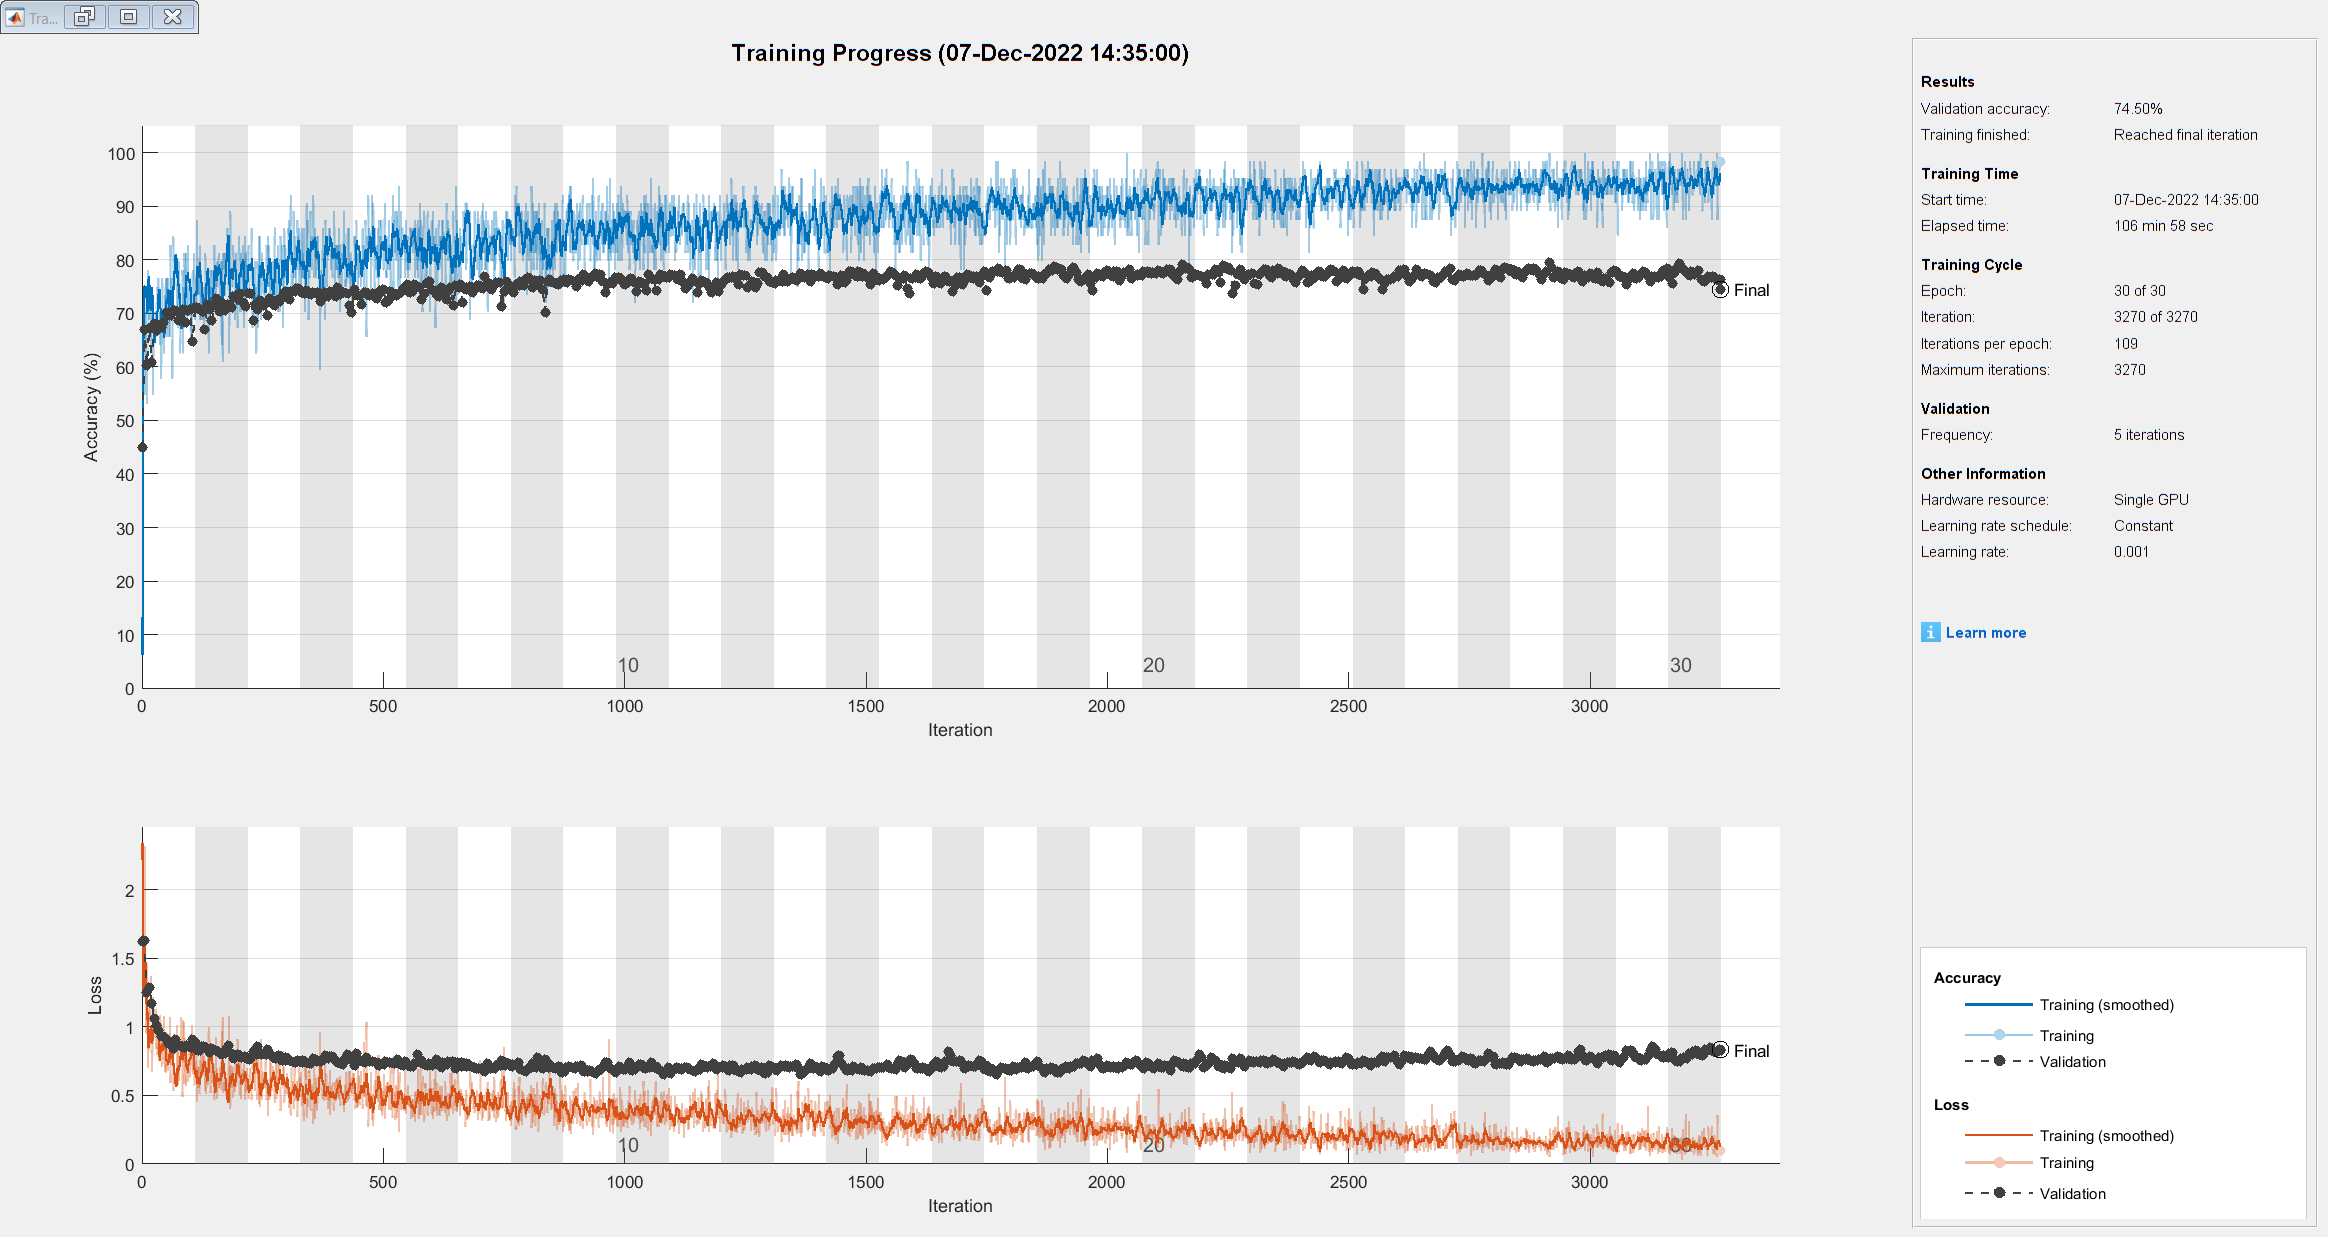

[net, traininfo] = trainNetwork(augimdsTrain,lgraph,opts);

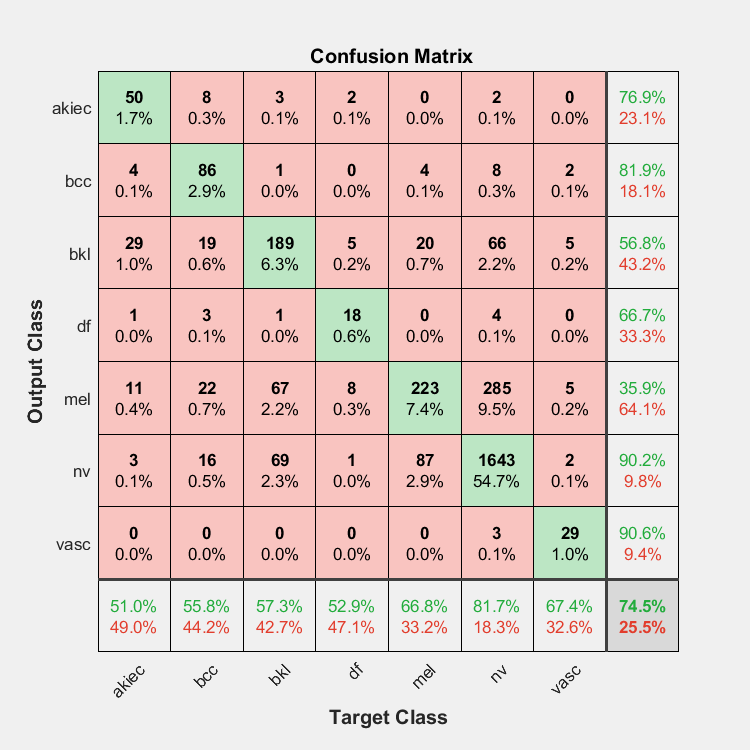

yPred = classify(net, imdsValidation);
yTest = imdsValidation.Labels;
plotconfusion(yTest, yPred)

figure
cm = confusionchart(yTest, yPred)

cm =   ConfusionMatrixChart with properties:

    NormalizedValues: [7×7 double]
         ClassLabels: [7×1 categorical]

  Show all properties


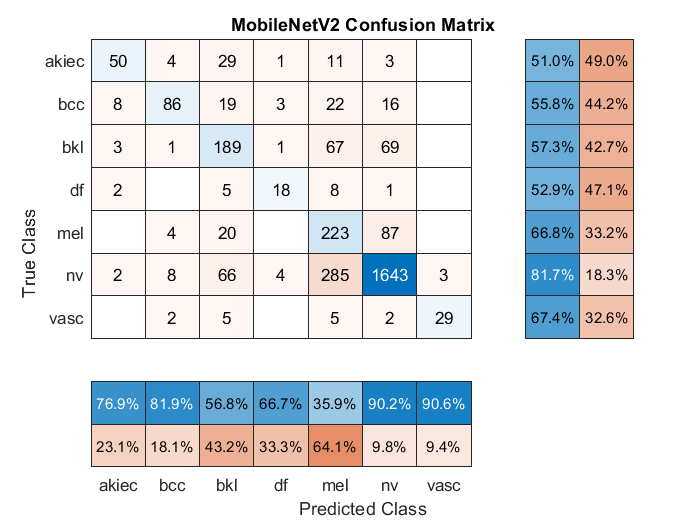

cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
cm.Title = 'MobileNetV2 Confusion Matrix';